# Geometric Mechanics motion planning of 4-CLARI

## Geometric Functions

addpath 'Utility Functions'\ Data\;
syms a l alpha_b alpha_1 alpha_2 alpha_3 alpha_4 real
syms alpha_i real

% we shall directly use mCLARI measurements
ll = 19; % in mm
aa = 4.75/ll; % length fraction of the link to one side of the robot
bl = 2*ll*cosd(45); % the length of the robot body outline
ab0= pi/4; % nominal sprawl angle


% arbitrary leg transform
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];

% SE(2) transforms
h_b__1b = [ l*sin(alpha_b)/2,  l*cos(alpha_b)/2, alpha_b]'; % body frame to hip frame 
h_b__2b = [-l*sin(alpha_b)/2,  l*cos(alpha_b)/2, pi-alpha_b]';
h_b__3b = [-l*sin(alpha_b)/2, -l*cos(alpha_b)/2, pi+alpha_b]';
h_b__4b = [ l*sin(alpha_b)/2, -l*cos(alpha_b)/2, -alpha_b]';

h_1b__1 = subs(h_ib__i, alpha_i, alpha_1); % hip frame to leg
h_2b__2 = subs(h_ib__i, alpha_i, alpha_2);
h_3b__3 = subs(h_ib__i, alpha_i, alpha_3);
h_4b__4 = subs(h_ib__i, alpha_i, alpha_4);

h_b__1 = simplify(seqSE2transformation([h_b__1b, h_1b__1])); % body frame to leg
h_b__2 = simplify(seqSE2transformation([h_b__2b, h_2b__2]));
h_b__3 = simplify(seqSE2transformation([h_b__3b, h_3b__3]));
h_b__4 = simplify(seqSE2transformation([h_b__4b, h_4b__4]));

h_b__12b = [              0,   l*cos(alpha_b),     alpha_b]'; % body frame to body sprawl joints
h_b__23b = [-l*sin(alpha_b),                0,  pi-alpha_b]';
h_b__34b = [              0,  -l*cos(alpha_b),  pi+alpha_b]';
h_b__41b = [ l*sin(alpha_b),                0,    -alpha_b]';

h_12b__1b = [0, -l/2, 0]'; % body sprawl joints to corresponding hip frames
h_12b__2b = simplify(seqSE2transformation( [[0, 0, pi-2*alpha_b]', [0, l/2, 0]'] ));
h_34b__3b = [0, -l/2, 0]';
h_34b__4b = simplify(seqSE2transformation( [[0, 0, pi-2*alpha_b]', [0, l/2, 0]'] ));

h_12b__1 = simplify(seqSE2transformation([h_12b__1b, h_1b__1])); % corresponding sprawl joints to legs
h_12b__2 = simplify(seqSE2transformation([h_12b__2b, h_2b__2]));
h_34b__3 = simplify(seqSE2transformation([h_34b__3b, h_3b__3]));
h_34b__4 = simplify(seqSE2transformation([h_34b__4b, h_4b__4]));

% defining unit velocities in theta SE(2) direction-- hip actuation velocities only include rotation
theta_dot = [0, 0, 1]';

% jacobians from body to leg
J_b__1 = adj_adjinv_SE2(v2M_SE2(h_b__1), -1);
J_b__2 = adj_adjinv_SE2(v2M_SE2(h_b__2), -1);
J_b__3 = adj_adjinv_SE2(v2M_SE2(h_b__3), -1);
J_b__4 = adj_adjinv_SE2(v2M_SE2(h_b__4), -1);

% jacobians from corresponding hip joints to each leg
J_1b__1 = adj_adjinv_SE2(v2M_SE2(h_1b__1), -1);
J_2b__2 = adj_adjinv_SE2(v2M_SE2(h_2b__2), -1);
J_3b__3 = adj_adjinv_SE2(v2M_SE2(h_3b__3), -1);
J_4b__4 = adj_adjinv_SE2(v2M_SE2(h_4b__4), -1);

% jacobians from sprawl joint to legs
J_12b__1 = adj_adjinv_SE2(v2M_SE2(h_12b__1), -1);
J_12b__2 = adj_adjinv_SE2(v2M_SE2(h_12b__2), -1);
J_34b__3 = adj_adjinv_SE2(v2M_SE2(h_34b__3), -1);
J_34b__4 = adj_adjinv_SE2(v2M_SE2(h_34b__4), -1);

% define the translational velocities selection matrix
Cxy = [eye(2,2), zeros(2,1)];

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% locked case-- CLARI maintains a fixed shape -----------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% full jacobians to each leg-- first 3 columns correspond to body velocity mapping; next 4 from each hip joint
lJ_1 = [J_b__1, zeros(3,0), J_1b__1*theta_dot, zeros(3,3)];
lJ_2 = [J_b__2, zeros(3,1), J_2b__2*theta_dot, zeros(3,2)];
lJ_3 = [J_b__3, zeros(3,2), J_3b__3*theta_dot, zeros(3,1)];
lJ_4 = [J_b__4, zeros(3,3), J_4b__4*theta_dot, zeros(3,0)];

% pfaffian constraints governing the non-slip, level-2 contact states
lpfaff_12 = [Cxy*lJ_1;
            Cxy*lJ_2];
lpfaff_23 = [Cxy*lJ_2;
            Cxy*lJ_3];
lpfaff_34 = [Cxy*lJ_3;
            Cxy*lJ_4];
lpfaff_41 = [Cxy*lJ_4;
            Cxy*lJ_1];
lpfaff_13 = [Cxy*lJ_1;
            Cxy*lJ_3];
lpfaff_24 = [Cxy*lJ_2;
            Cxy*lJ_4];

% squared inter-leg distance field F
lgt_12 = Cxy*(h_b__2 - h_b__1);
lgt_23 = Cxy*(h_b__3 - h_b__2);
lgt_34 = Cxy*(h_b__4 - h_b__3);
lgt_41 = Cxy*(h_b__1 - h_b__4);
lgt_13 = Cxy*(h_b__3 - h_b__1);
lgt_24 = Cxy*(h_b__4 - h_b__2);
lF_12 = simplify(transpose(lgt_12)*lgt_12, "Steps", 10);
lF_23 = simplify(transpose(lgt_23)*lgt_23, "Steps", 10);
lF_34 = simplify(transpose(lgt_34)*lgt_34, "Steps", 10);
lF_41 = simplify(transpose(lgt_41)*lgt_41, "Steps", 10);
lF_13 = simplify(transpose(lgt_13)*lgt_13, "Steps", 10);
lF_24 = simplify(transpose(lgt_24)*lgt_24, "Steps", 10);

% normalized gradient of F-- direction of strongest slip
lgradF_12u = simplify(gradient(lF_12, [alpha_1, alpha_2])); lnorm_gradF_12 = norm(lgradF_12u); lgradF_12 = simplify(lgradF_12u/lnorm_gradF_12);
lgradF_23u = simplify(gradient(lF_23, [alpha_2, alpha_3])); lnorm_gradF_23 = norm(lgradF_23u); lgradF_23 = simplify(lgradF_23u/lnorm_gradF_23);
lgradF_34u = simplify(gradient(lF_34, [alpha_3, alpha_4])); lnorm_gradF_34 = norm(lgradF_34u); lgradF_34 = simplify(lgradF_34u/lnorm_gradF_34);
lgradF_41u = simplify(gradient(lF_41, [alpha_4, alpha_1])); lnorm_gradF_41 = norm(lgradF_41u); lgradF_41 = simplify(lgradF_41u/lnorm_gradF_41);
lgradF_13u = simplify(gradient(lF_13, [alpha_1, alpha_3])); lnorm_gradF_13 = norm(lgradF_13u); lgradF_13 = simplify(lgradF_13u/lnorm_gradF_13);
lgradF_24u = simplify(gradient(lF_24, [alpha_2, alpha_4])); lnorm_gradF_24 = norm(lgradF_24u); lgradF_24 = simplify(lgradF_24u/lnorm_gradF_24);

% get the accessible shape velocity basis                                           [nonslip, strongest slip direction]
ldelta_alpha_12 = simplify(round(rot_SE2(-pi/2))*[lgradF_12; 0]); ldelta_alpha_12 = [ldelta_alpha_12(1:2), lgradF_12];
ldelta_alpha_23 = simplify(round(rot_SE2(-pi/2))*[lgradF_23; 0]); ldelta_alpha_23 = [ldelta_alpha_23(1:2), lgradF_23];
ldelta_alpha_34 = simplify(round(rot_SE2(-pi/2))*[lgradF_34; 0]); ldelta_alpha_34 = [ldelta_alpha_34(1:2), lgradF_34];
ldelta_alpha_41 = simplify(round(rot_SE2(-pi/2))*[lgradF_41; 0]); ldelta_alpha_41 = [ldelta_alpha_41(1:2), lgradF_41];
ldelta_alpha_13 = simplify(round(rot_SE2(-pi/2))*[lgradF_13; 0]); ldelta_alpha_13 = [ldelta_alpha_13(1:2), lgradF_13];
ldelta_alpha_24 = simplify(round(rot_SE2(-pi/2))*[lgradF_24; 0]); ldelta_alpha_24 = [ldelta_alpha_24(1:2), lgradF_24];

% the local connections for each of these contact states-- overconstrained first 4x3 matrix needs to be pseudoinverted
lA_12 = simplify(  ( transpose(lpfaff_12(:,1:3))*lpfaff_12(:,1:3) )\transpose(lpfaff_12(:,1:3)) *lpfaff_12(:,4:end), "Steps", 20  );
lA_23 = simplify(  ( transpose(lpfaff_23(:,1:3))*lpfaff_23(:,1:3) )\transpose(lpfaff_23(:,1:3)) *lpfaff_23(:,4:end), "Steps", 20  );
lA_34 = simplify(  ( transpose(lpfaff_34(:,1:3))*lpfaff_34(:,1:3) )\transpose(lpfaff_34(:,1:3)) *lpfaff_34(:,4:end), "Steps", 20  );
lA_41 = simplify(  ( transpose(lpfaff_41(:,1:3))*lpfaff_41(:,1:3) )\transpose(lpfaff_41(:,1:3)) *lpfaff_41(:,4:end), "Steps", 20  );
lA_13 = simplify(  ( transpose(lpfaff_13(:,1:3))*lpfaff_13(:,1:3) )\transpose(lpfaff_13(:,1:3)) *lpfaff_13(:,4:end), "Steps", 20  );
lA_24 = simplify(  ( transpose(lpfaff_24(:,1:3))*lpfaff_24(:,1:3) )\transpose(lpfaff_24(:,1:3)) *lpfaff_24(:,4:end), "Steps", 20  );

% the stratified panels for each of thes contact states: connection*shape_vel
ldz_12 = simplify(lA_12*[zeros(0,1)
               ldelta_alpha_12(1);
               zeros(0,1)
               ldelta_alpha_12(2);
               zeros(2,1)], "Steps", 20);
ldz_23 = simplify(lA_23*[zeros(1,1)
               ldelta_alpha_23(1);
               zeros(0,1)
               ldelta_alpha_23(2);
               zeros(1,1)], "Steps", 20);
ldz_34 = simplify(lA_34*[zeros(2,1)
               ldelta_alpha_34(1);
               zeros(0,1)
               ldelta_alpha_34(2);
               zeros(0,1)], "Steps", 20);
ldz_41 = simplify(lA_41*[zeros(0,1)
               ldelta_alpha_41(1);
               zeros(2,1)
               ldelta_alpha_41(2);
               zeros(0,1)], "Steps", 20);
ldz_13 = simplify(lA_13*[zeros(0,1)
               ldelta_alpha_13(1);
               zeros(1,1)
               ldelta_alpha_13(2);
               zeros(1,1)], "Steps", 20);
ldz_24 = simplify(lA_24*[zeros(1,1)
               ldelta_alpha_24(1);
               zeros(1,1)
               ldelta_alpha_24(2);
               zeros(0,1)], "Steps", 20);

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% unlocked case-- CLARI is free to change shape ---------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

uJ_1 = [J_b__1, J_12b__1*theta_dot, J_1b__1*theta_dot, zeros(3,3)];
uJ_2 = [J_b__2, J_12b__2*theta_dot, zeros(3,1), J_2b__2*theta_dot, zeros(3,2)];
uJ_3 = [J_b__3, J_34b__3*theta_dot, zeros(3,2), J_3b__3*theta_dot, zeros(3,1)];
uJ_4 = [J_b__4, J_34b__4*theta_dot, zeros(3,3), J_4b__4*theta_dot];

upfaff_12 = [Cxy*uJ_1;
            Cxy*uJ_2];
upfaff_23 = [Cxy*uJ_2;
            Cxy*uJ_3];
upfaff_34 = [Cxy*uJ_3;
            Cxy*uJ_4];
upfaff_41 = [Cxy*uJ_4;
            Cxy*uJ_1];
upfaff_13 = [Cxy*uJ_1;
            Cxy*uJ_3];
upfaff_24 = [Cxy*uJ_2;
            Cxy*uJ_4];

uF_12 = lF_12;
uF_23 = lF_23;
uF_34 = lF_34;
uF_41 = lF_41;
uF_13 = lF_13;
uF_24 = lF_24;

ugradF_12u = simplify(gradient(uF_12, [alpha_1, alpha_2, alpha_b])); unorm_gradF_12 = norm(ugradF_12u); ugradF_12 = simplify(ugradF_12u/unorm_gradF_12);
ugradF_23u = simplify(gradient(uF_23, [alpha_2, alpha_3, alpha_b])); unorm_gradF_23 = norm(ugradF_23u); ugradF_23 = simplify(ugradF_23u/unorm_gradF_23);
ugradF_34u = simplify(gradient(uF_34, [alpha_3, alpha_4, alpha_b])); unorm_gradF_34 = norm(ugradF_34u); ugradF_34 = simplify(ugradF_34u/unorm_gradF_34);
ugradF_41u = simplify(gradient(uF_41, [alpha_4, alpha_1, alpha_b])); unorm_gradF_41 = norm(ugradF_41u); ugradF_41 = simplify(ugradF_41u/unorm_gradF_41);
ugradF_13u = simplify(gradient(uF_13, [alpha_1, alpha_3, alpha_b])); unorm_gradF_13 = norm(ugradF_13u); ugradF_13 = simplify(ugradF_13u/unorm_gradF_13);
ugradF_24u = simplify(gradient(uF_24, [alpha_2, alpha_4, alpha_b])); unorm_gradF_24 = norm(ugradF_24u); ugradF_24 = simplify(ugradF_24u/unorm_gradF_24);

% get the accessible shape velocity basis-- both nonslip and slip directions (slip direction is the direction of shape change)
udelta_alpha_12 = simplify(round(rot_SE2(-pi/2))*[ugradF_12(1:2); 0]); udelta_alpha_12 = [udelta_alpha_12, ugradF_12];
udelta_alpha_23 = simplify(round(rot_SE2(-pi/2))*[ugradF_23(1:2); 0]); udelta_alpha_23 = [udelta_alpha_23, ugradF_23];
udelta_alpha_34 = simplify(round(rot_SE2(-pi/2))*[ugradF_34(1:2); 0]); udelta_alpha_34 = [udelta_alpha_34, ugradF_34];
udelta_alpha_41 = simplify(round(rot_SE2(-pi/2))*[ugradF_41(1:2); 0]); udelta_alpha_41 = [udelta_alpha_41, ugradF_41];
udelta_alpha_13 = simplify(round(rot_SE2(-pi/2))*[ugradF_13(1:2); 0]); udelta_alpha_13 = [udelta_alpha_13, ugradF_13];
udelta_alpha_24 = simplify(round(rot_SE2(-pi/2))*[ugradF_24(1:2); 0]); udelta_alpha_24 = [udelta_alpha_24, ugradF_24]; % for the whole connection

urdelta_alpha_12 = simplify(round(rot_SE2(-pi/2))*ugradF_12); urdelta_alpha_12 = [urdelta_alpha_12(1:2), ugradF_12(1:2)];
urdelta_alpha_23 = simplify(round(rot_SE2(-pi/2))*ugradF_23); urdelta_alpha_23 = [urdelta_alpha_23(1:2), ugradF_23(1:2)];
urdelta_alpha_34 = simplify(round(rot_SE2(-pi/2))*ugradF_34); urdelta_alpha_34 = [urdelta_alpha_34(1:2), ugradF_34(1:2)];
urdelta_alpha_41 = simplify(round(rot_SE2(-pi/2))*ugradF_41); urdelta_alpha_41 = [urdelta_alpha_41(1:2), ugradF_41(1:2)];
urdelta_alpha_13 = simplify(round(rot_SE2(-pi/2))*ugradF_13); urdelta_alpha_13 = [urdelta_alpha_13(1:2), ugradF_13(1:2)];
urdelta_alpha_24 = simplify(round(rot_SE2(-pi/2))*ugradF_24); urdelta_alpha_24 = [urdelta_alpha_24(1:2), ugradF_24(1:2)]; % for the reduced connection

% the local connections for each of these contact states-- overconstrained first 4x3 matrix needs to be pseudoinverted
uA_12 = simplify(  ( transpose(upfaff_12(:,1:3))*upfaff_12(:,1:3) )\transpose(upfaff_12(:,1:3)) *upfaff_12(:,4:end), "Steps", 20  );
uA_23 = simplify(  ( transpose(upfaff_23(:,1:3))*upfaff_23(:,1:3) )\transpose(upfaff_23(:,1:3)) *upfaff_23(:,4:end), "Steps", 20  );
uA_34 = simplify(  ( transpose(upfaff_34(:,1:3))*upfaff_34(:,1:3) )\transpose(upfaff_34(:,1:3)) *upfaff_34(:,4:end), "Steps", 20  );
uA_41 = simplify(  ( transpose(upfaff_41(:,1:3))*upfaff_41(:,1:3) )\transpose(upfaff_41(:,1:3)) *upfaff_41(:,4:end), "Steps", 20  );
uA_13 = simplify(  ( transpose(upfaff_13(:,1:3))*upfaff_13(:,1:3) )\transpose(upfaff_13(:,1:3)) *upfaff_13(:,4:end), "Steps", 20  );
uA_24 = simplify(  ( transpose(upfaff_24(:,1:3))*upfaff_24(:,1:3) )\transpose(upfaff_24(:,1:3)) *upfaff_24(:,4:end), "Steps", 20  );

% extract the "$alpha_b_dot" components (4th column) from each connection and replace them with the corresponding terms in limb swing velocity directions
urA_12 = reduce_2beatgait_noslip_connection(uA_12, 1, 2, ugradF_12);
urA_23 = reduce_2beatgait_noslip_connection(uA_23, 2, 3, ugradF_23);
urA_34 = reduce_2beatgait_noslip_connection(uA_34, 3, 4, ugradF_34);
urA_41 = reduce_2beatgait_noslip_connection(uA_41, 4, 1, ugradF_41);
urA_13 = reduce_2beatgait_noslip_connection(uA_13, 1, 3, ugradF_13);
urA_24 = reduce_2beatgait_noslip_connection(uA_24, 2, 4, ugradF_24);

% stratified panels for the local connections with gamma
udz_12 = simplify(uA_12*[udelta_alpha_12(3,:);
               zeros(0,2);
               udelta_alpha_12(1,:);
               zeros(0,2);
               udelta_alpha_12(2,:);
               zeros(2,2)], "Steps", 20);
udz_23 = simplify(uA_23*[udelta_alpha_23(3,:);
               zeros(1,2);
               udelta_alpha_23(1,:);
               zeros(0,2);
               udelta_alpha_23(2,:);
               zeros(1,2)], "Steps", 20);
udz_34 = simplify(uA_34*[udelta_alpha_34(3,:);
               zeros(2,2);
               udelta_alpha_34(1,:);
               zeros(0,2);
               udelta_alpha_34(2,:);
               zeros(0,2)], "Steps", 20);
udz_41 = simplify(uA_41*[udelta_alpha_41(3,:);
               zeros(0,2);
               udelta_alpha_41(1,:);
               zeros(2,2);
               udelta_alpha_41(2,:);
               zeros(0,2)], "Steps", 20);
udz_13 = simplify(uA_13*[udelta_alpha_13(3,:);
               zeros(0,2);
               udelta_alpha_13(1,:);
               zeros(1,2);
               udelta_alpha_13(2,:);
               zeros(1,2)], "Steps", 20);
udz_24 = simplify(uA_24*[udelta_alpha_24(3,:);
               zeros(1,2);
               udelta_alpha_24(1,:);
               zeros(1,2);
               udelta_alpha_24(2,:);
               zeros(0,2)], "Steps", 20);

                                            % without gamma
urdz_12 = simplify(urA_12*[zeros(0,2)
               urdelta_alpha_12(1,:);
               zeros(0,2)
               urdelta_alpha_12(2,:);
               zeros(2,2)], "Steps", 20);
urdz_23 = simplify(urA_23*[zeros(1,2)
               urdelta_alpha_23(1,:);
               zeros(0,2)
               urdelta_alpha_23(2,:);
               zeros(1,2)], "Steps", 20);
urdz_34 = simplify(urA_34*[zeros(2,2)
               urdelta_alpha_34(1,:);
               zeros(0,2)
               urdelta_alpha_34(2,:);
               zeros(0,2)], "Steps", 20);
urdz_41 = simplify(urA_41*[zeros(0,2)
               urdelta_alpha_41(1,:);
               zeros(2,2)
               urdelta_alpha_41(2,:);
               zeros(0,2)], "Steps", 20);
urdz_13 = simplify(urA_13*[zeros(0,2)
               urdelta_alpha_13(1,:);
               zeros(1,2)
               urdelta_alpha_13(2,:);
               zeros(1,2)], "Steps", 20);
urdz_24 = simplify(urA_24*[zeros(1,2)
               urdelta_alpha_24(1,:);
               zeros(1,2)
               urdelta_alpha_24(2,:);
               zeros(0,2)], "Steps", 20);

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% pack data ---------------------------------------------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Let's create functions and load all of this into a kinematics structure
clari_kin = []; clari_kin.params = []; clari_kin.sym = []; clari_kin.functions = [];

clari_kin.params.aa  = aa;
clari_kin.params.ll  = ll;
clari_kin.params.bl  = bl;
clari_kin.params.ab0 = ab0;

cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];
clari_kin.cSubmanifolds = cs;

for i = 1:4                                                                                
    % Symbolic transforms and jacobians
    clari_kin.sym. ...
        (['h_b__' num2str(i) 'b']) = eval(['h_b__' num2str(i) 'b']);
    clari_kin.sym. ...
        (['h_' num2str(i) 'b__' num2str(i)]) = eval(['h_' num2str(i) 'b__' num2str(i)]);
    clari_kin.sym. ...
        (['h_b__' num2str(i)]) = eval(['h_b__' num2str(i)]);
    clari_kin.sym. ...
        (['lJ_' num2str(i)]) = eval(['lJ_' num2str(i)]);
    clari_kin.sym. ...
        (['uJ_' num2str(i)]) = eval(['uJ_' num2str(i)]);
    % Functional transforms and jacobians
    clari_kin.functions. ...
        (['h_b__' num2str(i) 'b_f']) = matlabFunction(eval(['h_b__' num2str(i) 'b']), "Vars", [a l alpha_b]);
    clari_kin.functions. ...
        (['h_' num2str(i) 'b__' num2str(i) '_f']) = matlabFunction(eval(['h_' num2str(i) 'b__' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['h_b__' num2str(i) '_f']) = matlabFunction(eval(['h_b__' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['lJ_' num2str(i)]) =  matlabFunction(eval(['lJ_' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['uJ_' num2str(i)]) =  matlabFunction(eval(['uJ_' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
end

clari_kin.sym.h_b__12b = h_b__12b;
clari_kin.sym.h_b__23b = h_b__23b;
clari_kin.sym.h_b__34b = h_b__34b;
clari_kin.sym.h_b__41b = h_b__41b;
clari_kin.sym.h_b__12b_f = matlabFunction(h_b__12b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__23b_f = matlabFunction(h_b__23b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__34b_f = matlabFunction(h_b__34b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__41b_f = matlabFunction(h_b__41b, "Vars", [a l alpha_b]);

for i = 1:size(cs,1)
    % pfaffian constraints
    clari_kin.sym.(['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.sym.(['upfaff_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['upfaff_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions. ...
        (['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))])] ); % func
    clari_kin.functions. ...
        (['upfaff_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['upfaff_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))])] ); % func
    % scalar field F
    clari_kin.sym.(['lF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['lF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.sym.(['uF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['uF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions.(['lF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['lF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % func
    clari_kin.functions.(['uF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['uF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % func
    % contact submanifold information-- easier to save this elementwise
        % gradient of F in the shape space
    clari_kin.sym.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym var
    clari_kin.sym.(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.functions.(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );                         % norm value function
    clari_kin.sym.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u']) = eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))  'u']);
    clari_kin.sym.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym var
    clari_kin.sym.(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.functions.(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );                         % norm value function
    clari_kin.functions.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u_f']) = ...
        cell(numel(eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u'])), 1); % initialize func var
    clari_kin.functions.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u_f']) = ...
        cell(numel(eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u'])), 1); % initialize func var
    clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    for j = 1:numel(eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))]))                                                 % different sizes and hence done separately
        clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u_f']){j} = ...
            matlabFunction( eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % compute and store func var elementwise 
        clari_kin.functions.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); 
    end
    for j = 1:numel(eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))]))
        clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u_f']){j} = ...
            matlabFunction( eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) 'u(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
    end
        % the shape change basis
    clari_kin.sym.(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions.(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    for j = 1:numel(eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]))
        clari_kin.functions.(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
    end
    clari_kin.functions.(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(size(eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]))); % initialize func var
    for j = 1:size(eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(size(eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]))); % initialize func var
    for j = 1:size(eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
        % local connection
    clari_kin.sym.(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]); % reduced connection only in the unlocked case
    clari_kin.functions.(['lA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)                                              % different matrix sizes and hence different loops
        for k = 1:size(eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['lA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['uA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['uA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['urA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]))); % reduced connection only in the unlocked case
    for j = 1:size(eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['urA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
        % stratified panels
    clari_kin.sym.(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]); % reduced connection only in the unlocked case
    clari_kin.functions.(['ldz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)                                              % different matrix sizes and hence different loops
        for k = 1:size(eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['ldz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['udz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['udz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['urdz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]))); % reduced connection only in the unlocked case
    for j = 1:size(eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['urdz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
end

% Save the data
if exist('Data\4clari.mat', 'file')
    save('Data\4clari.mat', "a", "l", "alpha_b", "alpha_1", "alpha_2", "alpha_3", "alpha_4", "alpha_i", ... % set up in such a way that symbolic variables will be directly loaded into the workspace
        "clari_kin", "-append");
else
    save('Data\4clari.mat', "a", "l", "alpha_b", "alpha_1", "alpha_2", "alpha_3", "alpha_4", "alpha_i", ...
        "clari_kin");
end

## CLARI plotting setup

addpath 'Utility Functions'\ Data\; 
load('Data\4clari.mat');

% Let's define the body frame vector wrt to a rest frame
syms x y theta real
g_b = v2M_SE2([x, y, theta]');
rot_b = rot_SE2(theta);

% Symbolic formulae
% --------------------------------------------------------------------------------------------------------------------------------------------------------------------------

% Get the clari body and shape outlines-- shape outline is the smallest rectangle that fits the shape of CLARI
tempF = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__12b, clari_kin.sym.h_b__23b, clari_kin.sym.h_b__34b, clari_kin.sym.h_b__41b, clari_kin.sym.h_b__12b], ...
    3, ones(1, 5))...
    )), 3, 3*ones(1, 5))));

body_outline_x = tempF(1, :)'; body_outline_y = tempF(2, :)';

tempF = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__41b(1), clari_kin.sym.h_b__23b(1), clari_kin.sym.h_b__23b(1), clari_kin.sym.h_b__41b(1), clari_kin.sym.h_b__41b(1);
            clari_kin.sym.h_b__12b(2:3), clari_kin.sym.h_b__12b(2:3), clari_kin.sym.h_b__34b(2:3), clari_kin.sym.h_b__34b(2:3), clari_kin.sym.h_b__12b(2:3)], ...
            3, ones(1, 5))...
    )), 3, 3*ones(1, 5))));

shape_outline_x = tempF(1, :)'; shape_outline_y = tempF(2, :)';

% Get the body frame quivers

frame_x = g_b(1, 3)*ones(1, 2)'; frame_y = g_b(2, 3)*ones(1, 2)'; frame_u = g_b(1, 1:2)'; frame_v = g_b(2, 1:2)';

% legs individually
tempF = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__1, clari_kin.sym.h_b__2, clari_kin.sym.h_b__3, clari_kin.sym.h_b__4], ...
            3, ones(1, 4))...
    )), 3, 3*ones(1, 4))));

legs_x = tempF(1, :)'; legs_y = tempF(2, :)'; % leg tips

tempF = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__1b, clari_kin.sym.h_b__2b, clari_kin.sym.h_b__3b, clari_kin.sym.h_b__4b], ...
            3, ones(1, 4))...
    )), 3, 3*ones(1, 4))));

legsQ_x = tempF(1, :)'; legsQ_y = tempF(2, :)'; % to plot legs as quivers-- x and y mark the location of the base

tempF = cell2sym(SE2_mat2vec(mat2cell(rot_b*cell2sym(SE2_vec2mat( ...
    mat2cell([simplify(clari_kin.sym.h_b__1 - clari_kin.sym.h_b__1b), ...
                simplify(clari_kin.sym.h_b__2 - clari_kin.sym.h_b__2b), ...
                simplify(clari_kin.sym.h_b__3 - clari_kin.sym.h_b__3b), ...
                simplify(clari_kin.sym.h_b__4 - clari_kin.sym.h_b__4b)], ...
            3, ones(1, 4))...
    )), 3, 3*ones(1, 4))));

legsQ_u = tempF(1, :)'; legsQ_v = tempF(2, :)'; % to plot legs as quivers-- u and v give the length of the leg "vectors" M2v_SE2

% Matlab Functions ----------------------------
body_outline_x_f = matlabFunction(body_outline_x, "Vars", [a, l, x, y, theta, alpha_b]);
body_outline_y_f = matlabFunction(body_outline_y, "Vars", [a, l, x, y, theta, alpha_b]);
shape_outline_x_f = matlabFunction(shape_outline_x, "Vars", [a, l, x, y, theta, alpha_b]);
shape_outline_y_f = matlabFunction(shape_outline_y, "Vars", [a, l, x, y, theta, alpha_b]);
frame_x_f = matlabFunction(frame_x, "Vars", [a, l, x, y, theta]);
frame_y_f = matlabFunction(frame_y, "Vars", [a, l, x, y, theta]);
frame_u_f = matlabFunction(frame_u, "Vars", [a, l, x, y, theta]);
frame_v_f = matlabFunction(frame_v, "Vars", [a, l, x, y, theta]);
legs_x_f = matlabFunction(legs_x, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legs_y_f = matlabFunction(legs_y, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_x_f = matlabFunction(legsQ_x, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_y_f = matlabFunction(legsQ_y, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_u_f = matlabFunction(legsQ_u, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_v_f = matlabFunction(legsQ_v, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);

% Save all of it to the clari kinematic structure

clari_kin.sym.body_outline_x = body_outline_x;
clari_kin.sym.body_outline_y = body_outline_y;
clari_kin.sym.shape_outline_x = shape_outline_x;
clari_kin.sym.shape_outline_y = shape_outline_y;
clari_kin.sym.frame_x = frame_x;
clari_kin.sym.frame_y = frame_y;
clari_kin.sym.frame_u = frame_u;
clari_kin.sym.frame_v = frame_v;
clari_kin.sym.legs_x = legs_x;
clari_kin.sym.legs_y = legs_y;
clari_kin.sym.legsQ_x = legsQ_x;
clari_kin.sym.legsQ_y = legsQ_y;
clari_kin.sym.legsQ_u = legsQ_u;
clari_kin.sym.legsQ_v = legsQ_v;

clari_kin.functions.body_outline_x_f = body_outline_x_f;
clari_kin.functions.body_outline_y_f = body_outline_y_f;
clari_kin.functions.shape_outline_x_f = shape_outline_x_f;      %  body and shape outline plots
clari_kin.functions.shape_outline_y_f = shape_outline_y_f;
clari_kin.functions.frame_x_f = frame_x_f;                      % body frame quivers
clari_kin.functions.frame_y_f = frame_y_f;
clari_kin.functions.frame_u_f = frame_u_f;
clari_kin.functions.frame_v_f = frame_v_f;
clari_kin.functions.legs_x_f = legs_x_f;                        % scatter leg tips
clari_kin.functions.legs_y_f = legs_y_f;
clari_kin.functions.legsQ_x_f = legsQ_x_f;                      % leg quivers
clari_kin.functions.legsQ_y_f = legsQ_y_f;
clari_kin.functions.legsQ_u_f = legsQ_u_f;
clari_kin.functions.legsQ_v_f = legsQ_v_f;

% Save the data
save('Data\4clari.mat', "clari_kin", "-append");

## A system snapshot

Here, we shall use the functions generated above to create a snapshot of the shape-locked CLARI at the nominal and extreme configurations.

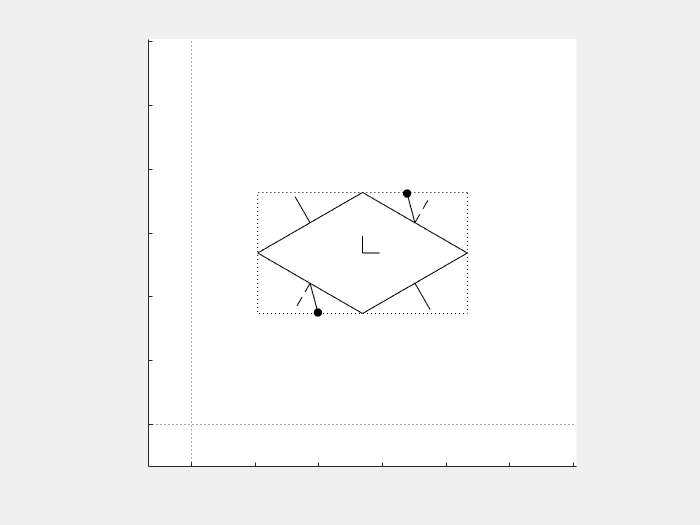

% load paths and data
addpath 'Utility Functions'\ Data\; load Data\4clari.mat;

% Setup a trajectory structure
traj = [];
traj{1} = [clari_kin.params.bl, clari_kin.params.bl, 0, pi/3, [pi/4, 0, pi/4, 0]]';
traj{2} = mat2cell(zeros(21, 1), 3*ones(1,7), 1);    % color of everything plottable
traj{3} = 5;                                         % active submanifold for this snapshot
traj{4} = nan;
traj{5} = 1;                                         % plot the body configuration
traj{6} = 1;                                         % number of frames

% Obtain the plot_trajectory struct
pltTraj = compute_pltTraj_clari(clari_kin, traj);

% define a plotting struct
pltTraj.plot_info = [];
scal = 23.5*clari_kin.params.bl/27; % /4
scaleDraw = max([diff(pltTraj.anim_lim(1:2)),diff(pltTraj.anim_lim(3:4))])/scal; % 23.5
pltTraj.plot_info.lW = 1.2/scaleDraw; pltTraj.plot_info.circS = 75/scaleDraw; pltTraj.plot_info.frame_scale = 0.10*clari_kin.params.bl;
pltTraj.plot_info.lW_r = 0.5/scaleDraw; pltTraj.plot_info.lW_s = 2.0/scaleDraw; pltTraj.plot_info.lW_b = 0.8/scaleDraw;
pltTraj.plot_info.lW_kq = 0.6/scaleDraw; pltTraj.plot_info.lW_qf = 0.8/scaleDraw;

% plot the snapshot of the robot
figure()
set(gcf,'Visible','on'); % pop-out the current figure
ax = gca; hA = plot_SE2snapshot_QLvl2_clari_NoSlip(ax, pltTraj);

## Accessible Shape Space

The reduced shape space is more restricted at a inter-leg distance because a sprawl might not exist for all possible configurations-- therefore, here we shall model the boundaries of the accessible shape as as functions of their centroid.

addpath 'Data'\ 'Utility Functions'\; load Data\4clari.mat;

% colormap --- F
jetDark = flipud([174,1,126; % diverging pink to blue
           221,52,151;
           247,104,161;
           250,159,181;
           116,169,207;
           54,144,192])/255;
jetDark = interp1(linspace(0,100,size(jetDark,1)), jetDark, linspace(0,100,size(jet,1))); % initialize the map based on colorbrewer
jP = sqrt(jetDark(:,1).^2 + jetDark(:,2).^2 + jetDark(:,3).^2); % power in each slice
jS = 1.1; % a proportional gain helping us shift the color levels % 0.8
jetDark = jS/max(jP)*repmat(jP,1,3).*jetDark; %%% proportional reduction with normalized power
jetDark(jetDark > 1) = 1; jetDark(jetDark < 0) = 0; % val between 0 and 1

%          --- Sprawl
CUB = flipud([159.3750,99.6030,63.4312;
              239.0625,149.4045,95.1469;
              255.0000,199.2060,126.8625;
                204,204,204;
                150,150,150;
                99,99,99])/255;
CUB = interp1( linspace(0,100,size(CUB,1)), CUB, linspace(0,100,size(turbo,1)) );
abS = linspace( clari_kin.params.ab0-clari_kin.params.ab_ank, ...
    clari_kin.params.ab0+clari_kin.params.ab_ank, ...
    size(CUB, 1) )'; % sprawl angles corresponding to this heatmap

% Set the hip limits of each limb and the sprawl limits of the body
clari_kin.params.ank = pi/2; % pi/2
clari_kin.params.ab_ank = pi/4;

% choose the contact states
csi = 1; csj = 3;

% Discretize the space
dnum = 101;
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ let's use the standard limits
% ab1 = linspace(clari_kin.params.ab0-clari_kin.params.ab_ank, ...
%     clari_kin.params.ab0+clari_kin.params.ab_ank, ...
%     dnum); % sprawl angles
% ai1 = linspace(-clari_kin.params.ank, ...
%     clari_kin.params.ank, ...
%     dnum);
% aj1 = ai1; % limb angles
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ let's use the max limits on these
ai1 = linspace(-pi, pi, dnum);
aj1 = ai1;                             % current shape space slice or stancing limb angles in CARTESIAN coordinates
ab1 = linspace(0, pi/2, dnum);         % sprawl angles
[ai, aj, ab] = meshgrid(ai1, aj1, ab1); % cylindrical coords with z being the sprawl angle, and x-y plane being the swing angles of the stancing legs

% compute the squared inter-leg distance, F
Fsweep = clari_kin.functions.uF_13_f(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);

% compute the component of the gradient along the sprawl direction
gFbSweep = clari_kin.functions.ugradF_13u_f{3}(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ method to get the derivatives symbolically
% % compute the gradF directions in i, j, and b-directions
% gF = simplify(gradient(clari_kin.sym.uF_13, [alpha_1, alpha_3, alpha_b]), "Steps", 10);
% gFi = matlabFunction(gF(1), 'Vars', [a, l, alpha_b, alpha_1, alpha_3]);
% gFj = matlabFunction(gF(2), 'Vars', [a, l, alpha_b, alpha_1, alpha_3]);
% gFb = matlabFunction(gF(3), 'Vars', [a, l, alpha_b, alpha_1, alpha_3]);
% % compute these sweeps
% gFi_sweep = gFi(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);
% gFj_sweep = gFj(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);
% gFb_sweep = gFb(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);

% some arrays to help computation
thetaSel = [0,0,1]; Cxy = [eye(2,2), zeros(2,1)];

% compute the maximum and minimum values of F
thetai = [0,0,1]*clari_kin.functions.(['h_b__' num2str(csi) 'b_f'])(clari_kin.params.aa, clari_kin.params.ll, ab1);
thetaj = [0,0,1]*clari_kin.functions.(['h_b__' num2str(csj) 'b_f'])(clari_kin.params.aa, clari_kin.params.ll, ab1);
ht__j2i = Cxy*( ...
    clari_kin.functions.(['h_b__' num2str(csi) 'b_f']) ...
    (clari_kin.params.aa, clari_kin.params.ll, ab1) ...
    - clari_kin.functions.(['h_b__' num2str(csj) 'b_f']) ...
    (clari_kin.params.aa, clari_kin.params.ll, ab1) ...
    );
midlink_j2i = atan2(ht__j2i(2, :),ht__j2i(1, :));
e__alpha_i = -thetai + midlink_j2i; 
e__alpha_j = -thetaj + midlink_j2i + pi;
c__alpha_i = -thetai + midlink_j2i + pi; 
c__alpha_j = -thetaj + midlink_j2i;
uF_Ubound = clari_kin.functions...
    .(['uF_' num2str(csi) num2str(csj) '_f'])...
    (clari_kin.params.aa, clari_kin.params.ll, ab1, e__alpha_i, e__alpha_j); % upper bound on F at each sprawl angle
uF_Lbound = clari_kin.functions...
    .(['uF_' num2str(csi) num2str(csj) '_f'])...
    (clari_kin.params.aa, clari_kin.params.ll, ab1, c__alpha_i, c__alpha_j); % lower bound on F at each sprawl angle
uF_range = uF_Ubound - uF_Lbound;                                            % range of the F at each sprawl angle
bFrac = 0.05;                                                                % bounding fraction for the required F range
uF_expUbound = uF_Ubound - 0.05*uF_range; 
uF_expLbound = uF_Lbound + 0.05*uF_range;                                    % reduced upper and lower bounds-- this is just to not work near the edge cases

% Discretizing F to choose a planning regime-- find the geometry at each F value
F = linspace(min(uF_expLbound), max(uF_expUbound), dnum);                    % range of F to find points at for each sprawl angle

% create a colormap for plotting F
colF = interp1( (1:size(jetDark, 1))', jetDark, linspace(bFrac*size(jetDark, 1), (1-bFrac)*size(jetDark, 1), dnum), 'spline' ); % create the colors
colF(colF > 1) = 1; colF(colF < 0) = 0;                                     % condition the interpolated colors
colF = mat2cell( colF, ones(1, size(colF, 1)),  size(colF, 2) )';           % separate into row-wise cells

% Initialize storage containers
Fctrs = cell(size(F)); branchNo = Fctrs; colAb = Fctrs;
centr = Fctrs; centr3 = Fctrs;
FctrsP = Fctrs; 
nullSprawlCtrs = cell(size(ab1)); FandNullSprwCtrs = Fctrs;

% iterate and compute the F-lvls
for i = 1:numel(F) % iterate over each F-level


    % compute the contours for current F-level at each sprawl angle ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    for j = 1:numel(ab1)
        tempF = contourc( ai1, aj1, Fsweep(:,:,j), F(i)*ones(1, 2) ); % get the contours
        if size(tempF, 2) > 1 % if this is not true, the function couldn't find any points
            % get the conditioned contour w/ or w/o the branch number
            switch isempty(branchNo{i})
                case 1
                    tempF = condition_contour2(tempF);
                case 0
                    tempF = condition_contour2(tempF, branchNo{i});
            end
            % get the branch number
            branchNo{i} = tempF(1, end);
            % add the new branch contours to the container
            Fctrs{i} = [ Fctrs{i}, [tempF(1,2:end); ab1(j)*ones(1, tempF(3,1)); tempF(2:end,2:end)] ];
        end
        
        % iterate and compute the points where the body sprawl gradient component vanishes
        if i == 1
            % get the zero contours of the 
            tempB = contourc(ai1, aj1, gFbSweep(:,:,j), zeros(1,2));
            % if solutions exist do, else move on
            if size(tempB, 2) > 1
                % condition the solutions
                tempB = condition_contour2(tempB);
                % get it to the form of [branchNo; sprawl; swing_i; swing_j];
                nullSprawlCtrs{j} = [  tempB(1, 2:end); ab1(j)*ones( 1, tempB(3,1) ); tempB(2:end, 2:end)  ];
                % [branchNo; sprawl; swing_i; swing_j; F_ij];
                nullSprawlCtrs{j}(end+1,:) = clari_kin.functions.uF_13_f(clari_kin.params.aa, clari_kin.params.ll,...
                    nullSprawlCtrs{j}(2,:), nullSprawlCtrs{j}(3,:), nullSprawlCtrs{j}(4,:)); 
            end
        end
    end

    % compute the 2D centroid (accessible shape space)
    centr{i} = mean(Fctrs{i}(3:end, :), 2);

    % compute the 3D centroid (accessible shape space)
    centr3{i} = mean(Fctrs{i}(2:end, :), 2);

    % compute the current F-level contours wrt to the centroid in polar coordinates
    p = Fctrs{i}(3:end, :)- centr{i};           % not taking the coordinates about the centroid anymore
    FctrsP{i}(1,:) = vecnorm(p, 2, 1);
    FctrsP{i}(2,:) = atan2(p(2,:), p(1,:));

    % compute the sprawl colors
    colAb{i} = interp1(abS, CUB, Fctrs{i}(2, :)');

end

% compute the F-contours that also have zero sprawl gradient ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
for j = 1:numel(ab1)
    % find the number of solutions and iterate over each solution
    N = nullSprawlCtrs{j}(1, end);
    % iterate over each solution branch
    for k = 1:N
        % current branch
        nSC = nullSprawlCtrs{j}(2:end, nullSprawlCtrs{j}(1,:) == k );
        % identify the F-lvls within range and approximate the points there
        idxF = ( F >= round(min(nSC(4, :)), 5) & F <= round(max(nSC(4, :)), 5) );
        if sum(idxF) ~= 0 % if some F-lvls are in range, iterate
            % make a polynomial fit
            idxN = 1:size(nSC, 2); % number of points in the branch
            ord = max([ceil(size(nSC, 2)/10) 1]); % polynomial order ~ "ceil" of 10% of number of points in the branch or at least order 1
            [pfit, ~, muFit] = polyfit(idxN', round(nSC(4, :)', 5), ord); % polynomial fit on the data rounded off to the 4th decimal place
            for l = find(idxF)
                % interpolate to the values we need
                pfitNow = pfit; pfitNow(end) = pfitNow(end) - F(l); % edit polynomial for desired F-lvl
                rNow = roots(pfitNow); 
                idxFit = muFit(2)*real(rNow(round(imag(rNow), 5) == 0)) + muFit(1);
                idxFit = idxFit(idxFit >= 1 & idxFit <= size(nSC, 2));               % condition the fit indices to proper index values
                if ~isempty(idxFit)
                    tempCtrs = interp1( idxN', nSC(1:3, :)', idxFit, 'spline' )';
                end
                % add the interpolated points to the container
                FandNullSprwCtrs{l} = [ FandNullSprwCtrs{l}, tempCtrs ];  
            end
        end
    end
end

% Bifurcation Surface Fit ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
startIdx = ceil(dnum/2); endIdx = dnum;  % heuristically obtained for S_13
aiB = []; ajB = []; abB = [];            % initialize empty container

% concatenate all the required solution branches
for i = startIdx:endIdx
    aiBnow = FandNullSprwCtrs{i}(2, :)'; 
    ajBnow = FandNullSprwCtrs{i}(3, :)'; 
    abBnow = FandNullSprwCtrs{i}(1, :)'; % B-- bifurcation surface
    switch i
        case 1
            aiB = aiBnow; 
            ajB = ajBnow; 
            abB = abBnow;
        otherwise
            aiB = [aiB; aiBnow]; 
            ajB = [ajB; ajBnow]; 
            abB = [abB; abBnow];
    end
end

% fit the surface
bifSurf_fit_type = fittype('poly55');
bifSurf_fit = fit([aiB, ajB], abB, bifSurf_fit_type);
ai2 = ai(:, :, 1); aj2 = aj(:, :, 1);
ab2_BifSurf = bifSurf_fit(ai2(:), aj2(:)); 
ab2_BifSurf = reshape(ab2_BifSurf, size(ai2, 1), size(aj2, 1));
F2_BifSurf = clari_kin.functions.uF_13_f...
    (clari_kin.params.aa, clari_kin.params.ll, ab2_BifSurf, ai2, aj2);

% compute F-lvls on the surface
Fc_BifSurf = cell(size(F)); bN_BifSurf = Fc_BifSurf; 
cen_BifSurf = Fc_BifSurf; FcP_BifSurf = Fc_BifSurf;
for i = 1:numel(F)
    tF_BifSurf = contourc( ai1, aj1, F2_BifSurf, F(i)*ones(1, 2) );
    if size(tF_BifSurf, 2) > 1
        switch isempty(bN_BifSurf{i})
            case 1
                tF_BifSurf = condition_contour2(tF_BifSurf);
            case 0
                tF_BifSurf = condition_contour2(tF_BifSurf, bN_BifSurf{i});
        end
        bN_BifSurf{i} = tF_BifSurf(1, end);
        Fc_BifSurf{i} = [ Fc_BifSurf{i}, tF_BifSurf(:, 2:end) ];
    end
    cen_BifSurf{i} = mean(Fc_BifSurf{i}(2:end, :), 2);
    p = Fc_BifSurf{i}(3:end, :)- cen_BifSurf{i};
    FcP_BifSurf{i}(1,:) = vecnorm(p, 2, 1);
    FcP_BifSurf{i}(2,:) = atan2(p(2,:), p(1,:));
end
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% get the current submanifold index
cs_idx = 5;

% store the plotting parameters
clari_kin.plot = [];
clari_kin.plot.jetDark = jetDark;   % overall color scheme for F
clari_kin.plot.colF{cs_idx} = colF; % colors for each F-lvl stored

% Store the computed data
clari_kin.data = [];
clari_kin.data.Fbounds{cs_idx}          = [uF_Lbound, uF_Ubound, uF_range, ...
                                            bFrac, uF_expLbound, uF_expUbound];
clari_kin.data.sweep{cs_idx}            = {ab, ai, aj, Fsweep, gFbSweep};
clari_kin.data.F{cs_idx}                = F;
clari_kin.data.Fctrs{cs_idx}            = Fctrs;
clari_kin.data.FctrsP{cs_idx}           = FctrsP;
clari_kin.data.centr{cs_idx}            = centr;
clari_kin.data.centr3{cs_idx}           = centr3;
clari_kin.data.branchNo{cs_idx}         = branchNo;
clari_kin.data.nullSprawlCtrs{cs_idx}   = nullSprawlCtrs;
clari_kin.data.FandNullSprwCtrs{cs_idx} = FandNullSprwCtrs;
clari_kin.data.bifSurf.fit_type{cs_idx} = bifSurf_fit_type; 
clari_kin.data.bifSurf.fit{cs_idx}      = bifSurf_fit; 
clari_kin.data.bifSurf.branchNo{cs_idx} = bN_BifSurf; 
clari_kin.data.bifSurf.Fctrs{cs_idx}    = Fc_BifSurf; 
clari_kin.data.bifSurf.centr{cs_idx}    = cen_BifSurf;
clari_kin.data.bifSurf.FctrsP{cs_idx}   = FcP_BifSurf;

% Save the data
save('Data\4clari.mat', "clari_kin", "-append");

The third component of the gradient as a function of the default (equilibrium) sprawl angle-- ~45$^\circ$

% % choose the submanifold you wanna work with
% cs_idx = 5;
% 
% % load the required dataset
% load('Data\4clari.mat');
% colF = clari_kin.plot.colF{cs_idx};
% branchNo = clari_kin.data.branchNo{cs_idx};
% Fctrs = clari_kin.data.Fctrs{cs_idx};
% % nullSprawlCtrs = clari_kin.data.nullSprawlCtrs{cs_idx};
% ai = clari_kin.data.sweep{cs_idx}{2}; 
% aj = clari_kin.data.sweep{cs_idx}{3};
% gFbSweep = clari_kin.data.sweep{cs_idx}{5};
% 
% % setup up some params
% dnum = numel(Fctrs);
% 
% % create animation
% vid_name = 'nullsprawlcontours';
% % vid_name = 'nullsprawlcontours_top';
% video = VideoWriter([vid_name,'.mp4'],'MPEG-4');
% video.FrameRate = 10;
% video.Quality = 100;
% open(video);
% 
% fig = figure('units','pixels','position',[100 0 1200 600],'Color','w'); % 100 -200
% set(fig,'Visible','on');
% ax = gca; grid(ax, "on"); view(-37.5, 30);
% for idx = 1:dnum
%     ai1 = reshape(       ai(:, :, idx), [dnum, dnum]); 
%     aj1 = reshape(       aj(:, :, idx), [dnum, dnum]); 
%     gFb = reshape(gFbSweep(:, :, idx), [dnum, dnum]);
%     surf(ax, ai1, aj1, gFb, 'LineStyle', 'none', 'FaceAlpha', 0.5);
%     hold on;
%     colormap(ax, "winter"); colorbar(ax);
%     view(45, 30); % video 1 isometric
%     % view(0, 90); % video 2 top axis equal;
%     contour(ax, ai1, aj1, gFb, zeros(1, 2), 'LineWidth', 1.2, 'Color', 'k'); drawnow;
%     % plot(nullSprawlCtrs{idx}(xdx, :), nullSprawlCtrs{idx}(ydx, :), 'k.', 'LineWidth', 1.2);
%     writeVideo(video, getframe(fig));
%     hold off;
% end
% close(video);

Here, we interpolate to specific F-level on a null-sprawl contour branch.

% nullSprawlCtrs{1}(1,end)
% N = 1
% branchN = 2
% nSC = nullSprawlCtrs{N}(2:end, nullSprawlCtrs{N}(1,:) == branchN ); % current branch
% size(nSC, 2) % number of points
% idxN = 1:size(nSC, 2); % number of points in the branch
% ord = ceil(size(nSC, 2)/10); % polynomial order ~ "ceil" of 10% of number of points in the branch
% [pfit, Sfit, muFit] = polyfit(idxN', round(nSC(4, :)', 5), ord); % polynomial fit on the data rounded off to the 4th decimal place
% [Ffit, ~] = polyval(pfit, idxN', Sfit, muFit);
% pfit
% rangeF = [min(round(nSC(4, :), 5)), max(round(nSC(4, :), 5))]
% rangeF(1) == rangeF(2)
% F >= rangeF(1) & F <= rangeF(2)
% figure()
% ax = gca;
% plot(ax, nSC(4, :), 'kx');
% hold on;
% plot(ax, Ffit, 'bo');
% F
% Fq = 250; % set a query F to interpolate to
% yline(ax, Fq, 'r-');
% pfitNow = pfit; pfitNow(end) = pfitNow(end) - Fq;
% pfitNow
% rNow = roots(pfitNow)
% find(round(imag(rNow), 5) == 0)
% idxFit = muFit(2)*real(rNow(round(imag(rNow), 5) == 0)) + muFit(1)
% xline(ax, idxFit, 'r--');

Now, we find the corresponding shape variables,

% interp1(idxN', nSC(1:3, :)', idxFit, 'spline' )'

Let's iteratively do this in the loop in the above section and extract whatever we need.

Visualize the F-contours.

% % choose the submanifold you wanna work with
% cs_idx = 5;
% 
% % load the required dataset
% load('Data\4clari.mat');
% colF = clari_kin.plot.colF{cs_idx};
% branchNo = clari_kin.data.branchNo{cs_idx};
% Fctrs = clari_kin.data.Fctrs{cs_idx};
% 
% % % % % % %  rough visualization of the F-contours through a quick animation
% % create animation
% vid_name = 'isoFcontours_limbXY_sprawlZ';
% % vid_name = 'isoFcontours_stacked_limbXY_sprawlZ';
% video = VideoWriter([vid_name,'.mp4'],'MPEG-4');
% video.FrameRate = 10;
% video.Quality = 100;
% open(video);
% 
% % start plotting
% fig = figure('units','pixels','position',[100 0 1200 600],'Color','w'); % 100 -200
% set(fig,'Visible','on');
% ax = gca; grid(ax, "on"); view(-37.5, 30);
% axis equal;
% for idx = 1:numel(Fctrs)
%     skp = max([floor(branchNo{idx}/70) 1]);   % skip 2.5% of the branches
%     % skp = 1;                                % skip no branches
%     for b = 1:skp:branchNo{idx}
%         if b == 1+skp
%             hold(ax, "on");
%         end
%         bIdx = Fctrs{idx}(1, :) == b;
%         plot3(ax, Fctrs{idx}(3, bIdx), Fctrs{idx}(4, bIdx), Fctrs{idx}(2, bIdx), ...
%             '-', 'LineWidth', 1.2, 'Color', colF{idx}); % '.'
%     end
%     hold(ax, "off"); % if this is commented off, it preserves the previous F-lvls
%     drawnow; xlim([-pi, pi]); ylim([-pi, pi]); zlim([0, pi/2]); % limits on the shape vars
%     writeVideo(video, getframe(fig));                  % capture the frame
% end
% close(video); % this is a must to not get a corrupted file

Here, we visualize the bifurcation surface with $\alpha_b$-sliced contours of F.

% % choose the submanifold you wanna work with
% cs_idx = 5;
% 
% % load the required dataset
% load('Data\4clari.mat');
% colF = clari_kin.plot.colF{cs_idx};
% F = clari_kin.data.F{cs_idx};
% branchNo = clari_kin.data.branchNo{cs_idx};
% Fctrs = clari_kin.data.Fctrs{cs_idx};
% FandNullSprwCtrs = clari_kin.data.FandNullSprwCtrs{cs_idx};
% 
% % define params
% dnum = numel(Fctrs);
% bNo  = 1; 
% % xdx  = 3; ydx  = 4; zdx  = 2;
% xdxS = 2; ydxS = 3; zdxS = 1;
% 
% % start plotting
% fig = figure('units','pixels','position',[200 100 1200 600],'Color','w');
% set(fig,'Visible','on'); ax = gca;
% grid(ax, "on");hold (ax, "on"); axis equal;
% 
% % plot the alphab_b-sliced F-contours at the required range range vals
% numS = 10;
% idxFcont = floor(linspace(1, dnum, numS)); % ceil also works
% 
% for idx = 1:dnum
% 
%     % plot the bifurcation surface
%     plot3(ax, FandNullSprwCtrs{idx}(xdxS, :), FandNullSprwCtrs{idx}(ydxS, :), ...
%         FandNullSprwCtrs{idx}(zdxS, :), '.', 'LineWidth', 1.2, 'Color', colF{idx});
% 
%     % If the current F-contour is needed
%     if sum(idx == idxFcont) ~= 0
%         % skp = max([floor(branchNo{idx}/50) 1]); % not skipping branches right now
%         for b = 1:branchNo{idx} % :skp
%             bIdx = Fctrs{idx}(bNo, :) == b;
%             plot3(ax, Fctrs{idx}(3, bIdx), Fctrs{idx}(4, bIdx), Fctrs{idx}(2, bIdx), ... % plot the actual F-contour
%                 '-', 'LineWidth', 1.2, 'Color', colF{idx}); % '.'
%         end
%     end
% 
% end
% xlim(ax, [-pi, pi]); ylim(ax, [-pi, pi]); zlim(ax, [0, pi/2]);
% % view(-37.5, 20); % for video ([azimuthal, elevation] angles)
% view(3); % just for plot (dim)

% % create animation
% % vid_name = 'bifurcation_surface_fit_w5Fcontours';
% vid_name = ['bifurcation_surface_fit_w' num2str(numS) 'Fcontours'];
% video = VideoWriter([vid_name,'.mp4'],'MPEG-4');
% video.FrameRate = 30;
% video.Quality = 100;
% open(video);
% 
% frameN = video.FrameRate*5; % will result in a 5sec video
% 
% for i = 1:frameN
%     view(-37.5 + i*360/frameN, 20);
%     writeVideo(video, getframe(fig));
% end
% close(video);

Here, we visualize the whole surface.

% % choose the submanifold you wanna work with
% cs_idx = 5;
% 
% % load the required dataset
% load('Data\4clari.mat');
% colF = clari_kin.plot.colF{cs_idx};
% Fctrs = clari_kin.data.Fctrs{cs_idx};
% 
% % set some plot params
% dnum = numel(Fctrs); xdx = 3; ydx = 4; zdx = 2;
% 
% % % % % % % % % % % % % % % % %  rough boundary based accessible shape space approximation
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = 1; % lowest F
% % k1 = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', Fctrs{idx}(zdx,:)', shrinkLvl);
% figure()
% plot3(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:), '.', 'Color', colF{idx}); hold on; axis equal; xlim([-pi, pi]); ylim([-pi, pi]); zlim([0, pi/2]);
% % trisurf(k1, Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:),'Facecolor', 'red', 'FaceAlpha', 0.1, 'LineWidth', 0.01);
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = floor(dnum/4); % 25% of 1D F-range
% % k1 = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', Fctrs{idx}(zdx,:)', shrinkLvl);
% figure()
% plot3(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:), '.', 'Color', colF{idx}); hold on; axis equal; xlim([-pi, pi]); ylim([-pi, pi]); zlim([0, pi/2]);
% trisurf(k1, Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:),'Facecolor', 'red', 'FaceAlpha', 0.1, 'LineWidth', 0.01);
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = floor(dnum/2); % 50% of F
% % k1 = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', Fctrs{idx}(zdx,:)', shrinkLvl);
% figure()
% plot3(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:), '.', 'Color', colF{idx}); hold on; axis equal; xlim([-pi, pi]); ylim([-pi, pi]); zlim([0, pi/2]);
% % trisurf(k1, Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:),'Facecolor', 'red', 'FaceAlpha', 0.1, 'LineWidth', 0.01);
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = ceil(3*dnum/4); % 75% of F
% % k1 = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', Fctrs{idx}(zdx,:)', shrinkLvl);
% figure()
% plot3(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:), '.', 'Color', colF{idx}); hold on; axis equal; xlim([-pi, pi]); ylim([-pi, pi]); zlim([0, pi/2]);
% % trisurf(k1, Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:),'Facecolor', 'red', 'FaceAlpha', 0.1, 'LineWidth', 0.01);
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = dnum; % 100% of F
% % k1 = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', Fctrs{idx}(zdx,:)', shrinkLvl);
% figure()
% plot3(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:), '.', 'Color', colF{idx}); hold on; axis equal; xlim([-pi, pi]); ylim([-pi, pi]); zlim([0, pi/2]);
% % trisurf(k1, Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), Fctrs{idx}(zdx,:),'Facecolor', 'red', 'FaceAlpha', 0.1, 'LineWidth', 0.01);

Here, we try to classify the controlled and accessible shape space at each F.

% % choose the submanifold you wanna work with
% cs_idx = 5;
% 
% % load the required dataset
% load('Data\4clari.mat');
% colF = clari_kin.plot.colF{cs_idx};
% Fctrs = clari_kin.data.Fctrs{cs_idx};
% FctrsP = clari_kin.data.FctrsP{cs_idx};
% centr = clari_kin.data.centr{cs_idx};
% 
% % setup up some params
% dnum = numel(Fctrs);
% xdx = 3; ydx = 4; zdx = 2;
% rdxP = 1; thdxP = 2;
% 
% shrinkLvl = 1;
% % % % % % % % % % % % % % % % %  rough boundary based accessible shape space approximation
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = 1; % lowest F
% f = figure();
% plot(FctrsP{idx}(thdxP,:), '.', 'Color', colF{idx});
% title('just theta'); set(f,'Visible','on');
% f = figure();
% plot(FctrsP{idx}(thdxP,:), FctrsP{idx}(rdxP,:), 'r.', 'Color', colF{idx}); hold on;
% kP = boundary(FctrsP{idx}(thdxP,:)', FctrsP{idx}(rdxP,:)', shrinkLvl);
% k = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', shrinkLvl);
% plot(FctrsP{idx}(thdxP,kP), FctrsP{idx}(rdxP,kP), 'k-');
% plot(FctrsP{idx}(thdxP,k), FctrsP{idx}(rdxP,k), 'b--');
% hold off;
% title('polar'); set(f,'Visible','on');
% f = figure();
% plot(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), 'r.', 'Color', colF{idx}); hold on; axis equal square padded;
% plot(Fctrs{idx}(xdx,kP), Fctrs{idx}(ydx,kP), 'k-');
% plot(Fctrs{idx}(xdx,k), Fctrs{idx}(ydx,k), 'b--');
% plot(centr{idx}(1), centr{idx}(1), 'k+', 'LineWidth', 1.2, MarkerSize=25);
% hold off;
% title('cartesian'); set(f,'Visible','on');
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = floor(dnum/4); % quarter F
% f = figure();
% plot(FctrsP{idx}(thdxP,:), '.', 'Color', colF{idx});
% title('just theta'); set(f,'Visible','on');
% f = figure();
% plot(FctrsP{idx}(thdxP,:), FctrsP{idx}(rdxP,:), 'r.', 'Color', colF{idx}); hold on;
% kP = boundary(FctrsP{idx}(thdxP,:)', FctrsP{idx}(rdxP,:)', shrinkLvl);
% k = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', shrinkLvl);
% plot(FctrsP{idx}(thdxP,kP), FctrsP{idx}(rdxP,kP), 'k-');
% plot(FctrsP{idx}(thdxP,k), FctrsP{idx}(rdxP,k), 'b--');
% hold off;
% title('polar'); set(f,'Visible','on');
% f = figure();
% plot(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), 'r.', 'Color', colF{idx}); hold on; axis equal square padded;
% plot(Fctrs{idx}(xdx,kP), Fctrs{idx}(ydx,kP), 'k-');
% plot(Fctrs{idx}(xdx,k), Fctrs{idx}(ydx,k), 'b--');
% plot(centr{idx}(1), centr{idx}(2), 'k+', 'LineWidth', 1.2, MarkerSize=25);
% hold off;
% title('cartesian'); set(f,'Visible','on');
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = floor(dnum/2); % mid F
% f = figure();
% plot(FctrsP{idx}(thdxP,:), '.', 'Color', colF{idx});
% title('just theta'); set(f,'Visible','on');
% f = figure();
% plot(FctrsP{idx}(thdxP,:), FctrsP{idx}(rdxP,:), 'r.', 'Color', colF{idx}); hold on;
% kP = boundary(FctrsP{idx}(thdxP,:)', FctrsP{idx}(rdxP,:)', shrinkLvl);
% k = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', shrinkLvl);
% plot(FctrsP{idx}(thdxP,kP), FctrsP{idx}(rdxP,kP), 'k-');
% plot(FctrsP{idx}(thdxP,k), FctrsP{idx}(rdxP,k), 'b--');
% hold off;
% title('polar'); set(f,'Visible','on');
% f = figure();
% plot(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), 'r.', 'Color', colF{idx}); hold on; axis equal square padded;
% plot(Fctrs{idx}(xdx,kP), Fctrs{idx}(ydx,kP), 'k-');
% plot(Fctrs{idx}(xdx,k), Fctrs{idx}(ydx,k), 'b--');
% plot(centr{idx}(1), centr{idx}(1), 'k+', 'LineWidth', 1.2, MarkerSize=25);
% hold off;
% title('cartesian'); set(f,'Visible','on');
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = ceil(3*dnum/4); % 3 quarters F
% f = figure();
% plot(FctrsP{idx}(thdxP,:), '.', 'Color', colF{idx});
% title('just theta'); set(f,'Visible','on');
% f = figure();
% plot(FctrsP{idx}(thdxP,:), FctrsP{idx}(rdxP,:), 'r.', 'Color', colF{idx}); hold on;
% kP = boundary(FctrsP{idx}(thdxP,:)', FctrsP{idx}(rdxP,:)', shrinkLvl);
% k = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', shrinkLvl);
% plot(FctrsP{idx}(thdxP,kP), FctrsP{idx}(rdxP,kP), 'k-');
% plot(FctrsP{idx}(thdxP,k), FctrsP{idx}(rdxP,k), 'b--');
% hold off;
% title('polar'); set(f,'Visible','on');
% f = figure();
% plot(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), 'r.', 'Color', colF{idx}); hold on; axis equal square padded;
% plot(Fctrs{idx}(xdx,kP), Fctrs{idx}(ydx,kP), 'k-');
% plot(Fctrs{idx}(xdx,k), Fctrs{idx}(ydx,k), 'b--');
% plot(centr{idx}(1), centr{idx}(1), 'k+', 'LineWidth', 1.2, MarkerSize=25);
% hold off;
% title('cartesian'); set(f,'Visible','on');
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% idx = dnum; % highest F
% f = figure();
% plot(FctrsP{idx}(thdxP,:), '.', 'Color', colF{idx});
% title('just theta'); set(f,'Visible','on');
% f = figure();
% plot(FctrsP{idx}(thdxP,:), FctrsP{idx}(rdxP,:), 'r.', 'Color', colF{idx}); hold on;
% kP = boundary(FctrsP{idx}(thdxP,:)', FctrsP{idx}(rdxP,:)', shrinkLvl);
% k = boundary(Fctrs{idx}(xdx,:)', Fctrs{idx}(ydx,:)', shrinkLvl);
% plot(FctrsP{idx}(thdxP,kP), FctrsP{idx}(rdxP,kP), 'k-');
% plot(FctrsP{idx}(thdxP,k), FctrsP{idx}(rdxP,k), 'b--');
% hold off;
% title('polar'); set(f,'Visible','on');
% f = figure();
% plot(Fctrs{idx}(xdx,:), Fctrs{idx}(ydx,:), 'r.', 'Color', colF{idx}); hold on; axis equal square padded;
% plot(Fctrs{idx}(xdx,kP), Fctrs{idx}(ydx,kP), 'k-');
% plot(Fctrs{idx}(xdx,k), Fctrs{idx}(ydx,k), 'b--');
% plot(centr{idx}(1), centr{idx}(1), 'k+', 'LineWidth', 1.2, MarkerSize=25);
% hold off;
% title('cartesian'); set(f,'Visible','on');

Let's zoom in a little bit further to see where the bifurcation plane changes and reassign a working range of F (just the lower bound). From the previous section, we know this has to be less than 50% and greater than 25%.

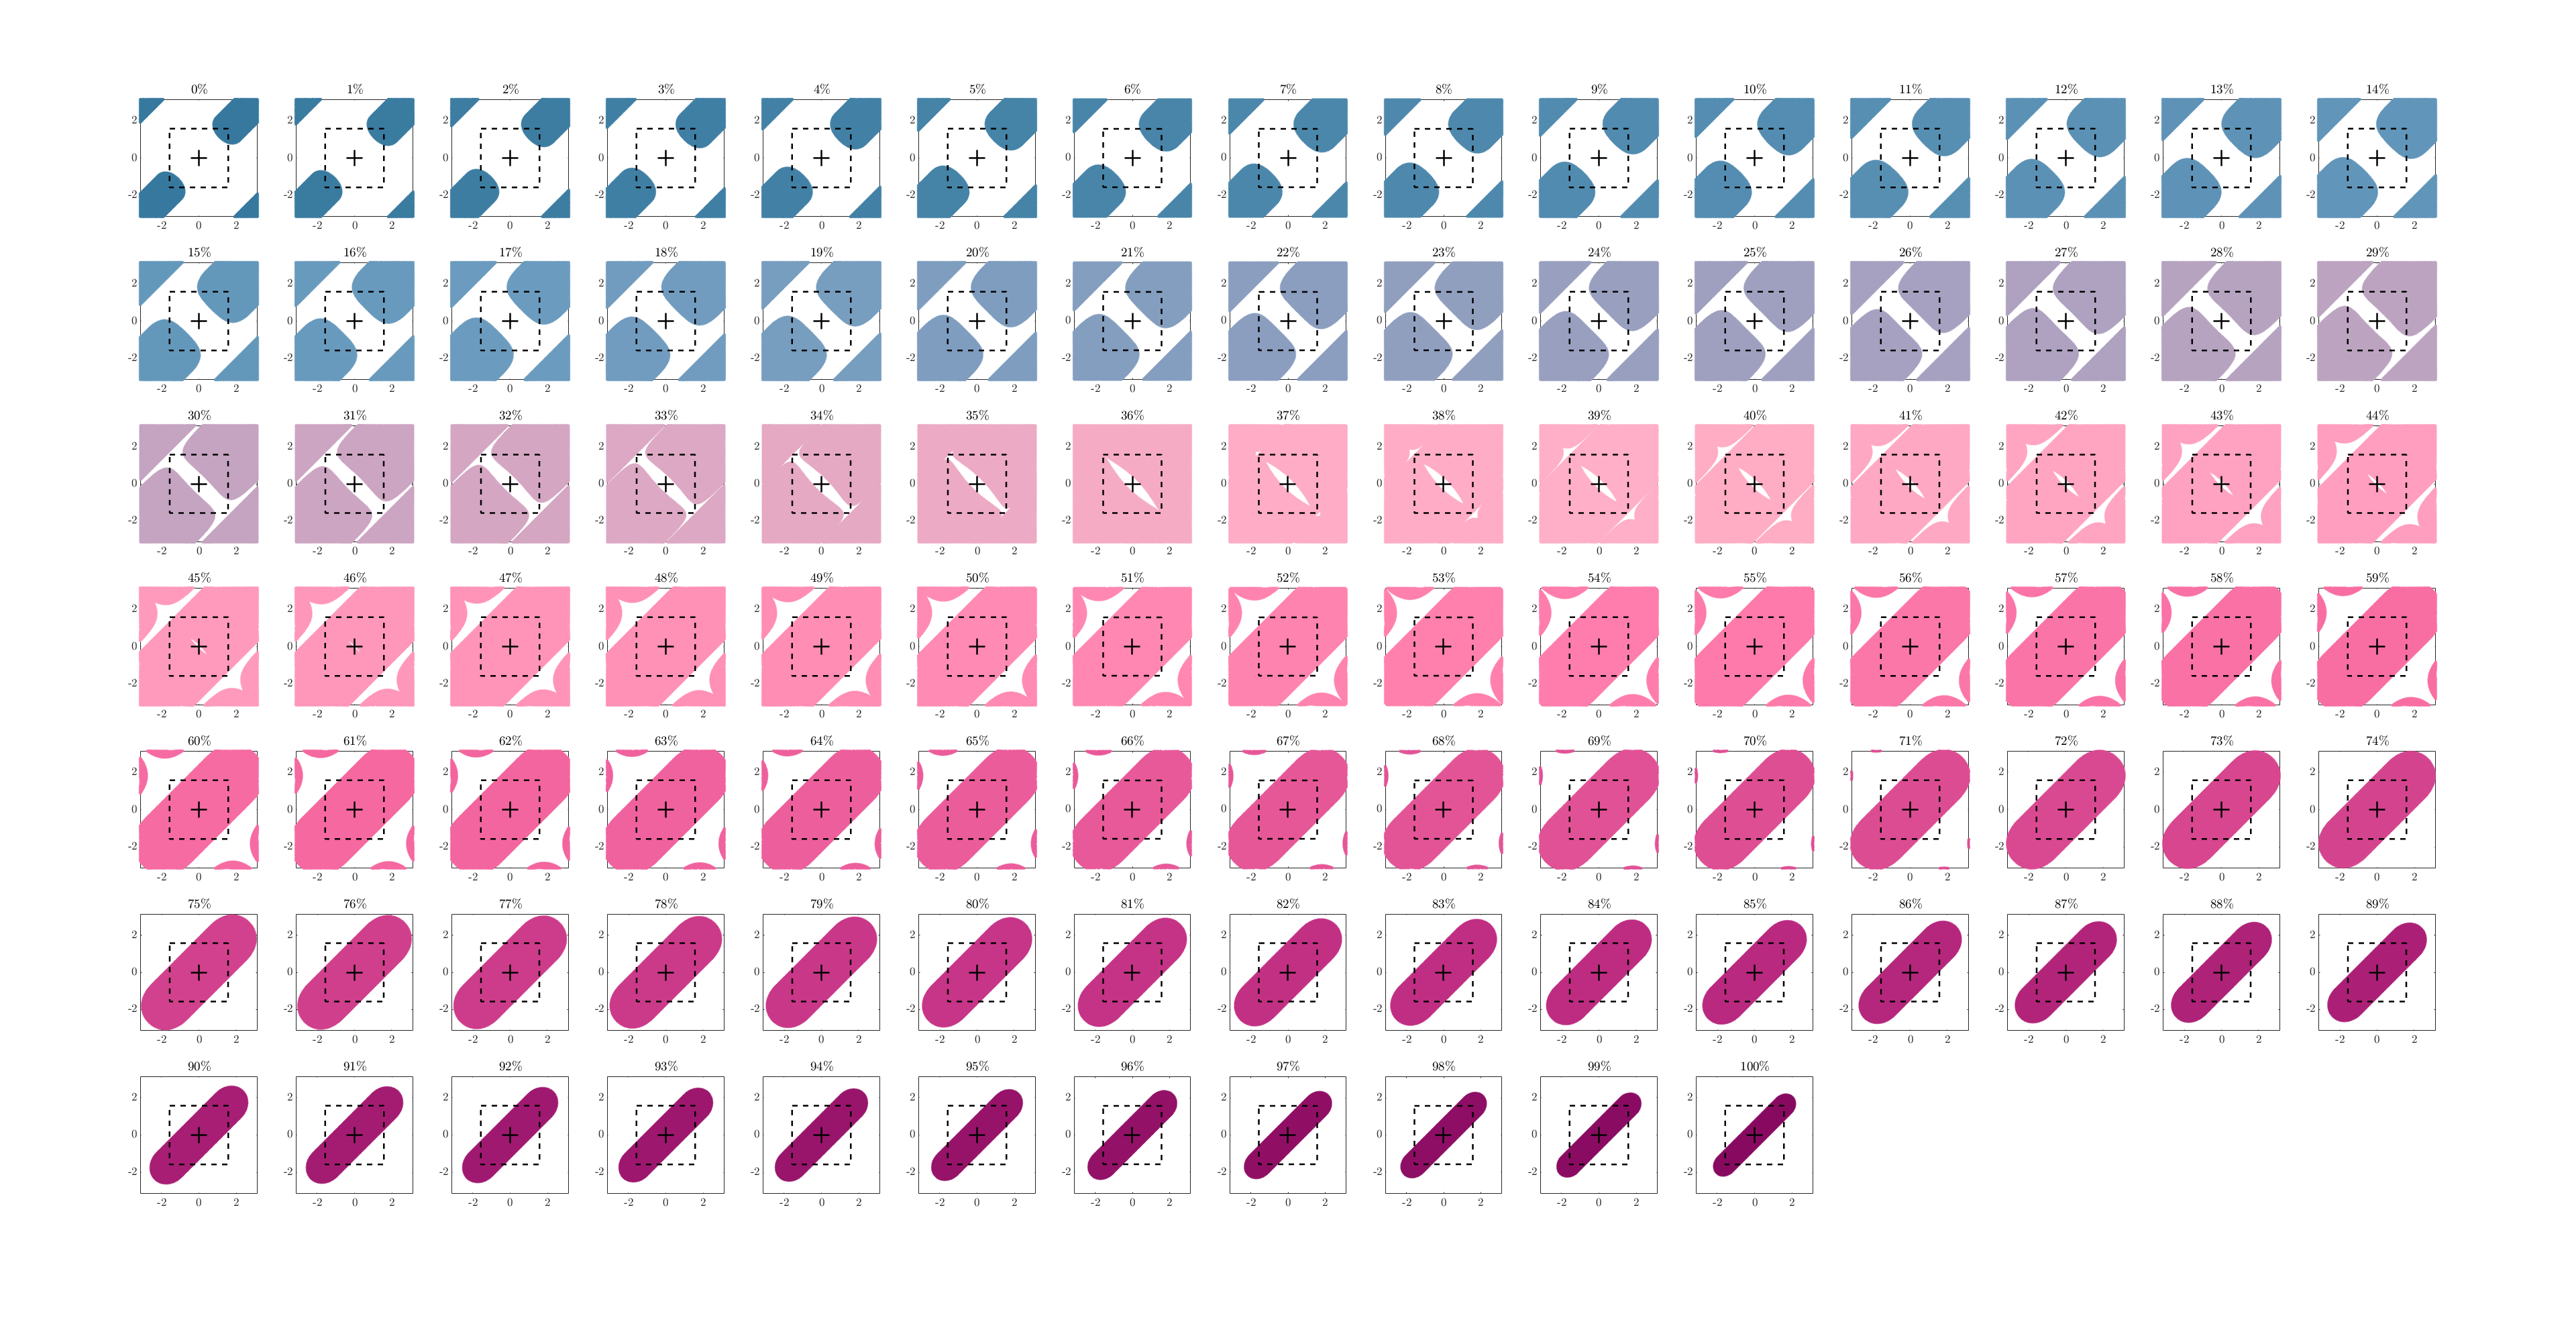

% choose the submanifold you wanna work with
cs_idx = 5;

% load the required dataset
load('Data\4clari.mat');
colF = clari_kin.plot.colF{cs_idx};
Fctrs = clari_kin.data.Fctrs{cs_idx};
centr = clari_kin.data.centr{cs_idx};

% setup up some params
dnum = numel(Fctrs);
xdx = 3; ydx = 4; zdx = 2;
rdxP = 1; thdxP = 2;
swing_lim = pi*[-1, 1];

% get the limit box coordinates
xBox = [-clari_kin.params.ank, clari_kin.params.ank, clari_kin.params.ank, -clari_kin.params.ank];
yBox = circshift([-clari_kin.params.ank, clari_kin.params.ank, clari_kin.params.ank, -clari_kin.params.ank], -1); % swing limits
xBox(end+1) = xBox(1); yBox(end+1) = yBox(1);
shrinkLvl = 1;

% % % % % % % % % % % % % % % %  F-lvls
% default latex interpreter
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% plot
f = figure('Color','w'); f.WindowState = 'maximized';
tiledlayout(f, 'flow');
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
prct = linspace(0, 100, dnum);
for i = 1:dnum
    nexttile
    plot(Fctrs{i}(xdx,:), Fctrs{i}(ydx,:), '.', 'Color', colF{i}); 
    hold on; axis equal square padded; xlim(swing_lim); ylim(swing_lim);
    plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=12);
    plot(xBox, yBox, 'k--', 'LineWidth', 1.2); % plot the systems limits box
    title(['$$' num2str(prct(i)) '\%$$'], 'Interpreter', 'latex');
end
set(gcf,'Visible','on');

50% seems to be the hard lower limit without a tear in the middle-- avoiding sections with holes.

Let's collect the last 50% of the defined range of F and do a polynomial fit to the bifurcation surface.

% choose the submanifold you wanna work with
cs_idx = 5;

% load the required dataset
load('Data\4clari.mat');
colF = clari_kin.plot.colF{cs_idx};
F = clari_kin.data.F{cs_idx};
branchNo = clari_kin.data.branchNo{cs_idx};
Fctrs = clari_kin.data.Fctrs{cs_idx};
FandNullSprwCtrs = clari_kin.data.FandNullSprwCtrs{cs_idx};
centr = clari_kin.data.centr{cs_idx};

% define params
dnum = numel(Fctrs);
bNo  = 1; 
xdx  = 3; ydx  = 4; zdx  = 2;
xdxS = 2; ydxS = 3; zdxS = 1;
fSiz = 12;

% get the limit box coordinates
xBox = [-clari_kin.params.ank, clari_kin.params.ank, clari_kin.params.ank, -clari_kin.params.ank];
yBox = circshift([-clari_kin.params.ank, clari_kin.params.ank, clari_kin.params.ank, -clari_kin.params.ank], -1); % swing limits
xBox(end+1) = xBox(1); yBox(end+1) = yBox(1);

% collect the bifurcation surface points into long vectors for the fitting procedure
startIdx = ceil(dnum/2); endIdx = dnum; 
aiB = []; ajB = []; abB = []; % initialize empty container
for i = startIdx:endIdx
    % get the current solutions
    aiBnow = FandNullSprwCtrs{i}(xdxS, :)'; 
    ajBnow = FandNullSprwCtrs{i}(ydxS, :)'; 
    abBnow = FandNullSprwCtrs{i}(zdxS, :)'; % B-- bifurcation surface
    % initialize if the first iteration and append from the next one
    switch i
        case 1
            aiB = aiBnow; 
            ajB = ajBnow; 
            abB = abBnow;
        otherwise
            aiB = [aiB; aiBnow]; 
            ajB = [ajB; ajBnow]; 
            abB = [abB; abBnow];
    end
end

% fit
bifSurf_fit_type = fittype('poly55');
bifSurf_fit = fit([aiB, ajB], abB, bifSurf_fit_type); % shows that the bifurcation surface is mostly a flat plane

% % % % % % % % % % % % % % % %  Bifurcation surface
% default latex interpreter
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% % plot
% f = figure('Color','w'); 
% f.WindowState = 'maximized';
% plot(bifSurf_fit, [aiB, ajB], abB);
% axis equal padded; 
% set(gcf,'Visible','on');

Great! Let's now plot the bifurcation surface as $\alpha_b$-contours and $F$-contours.

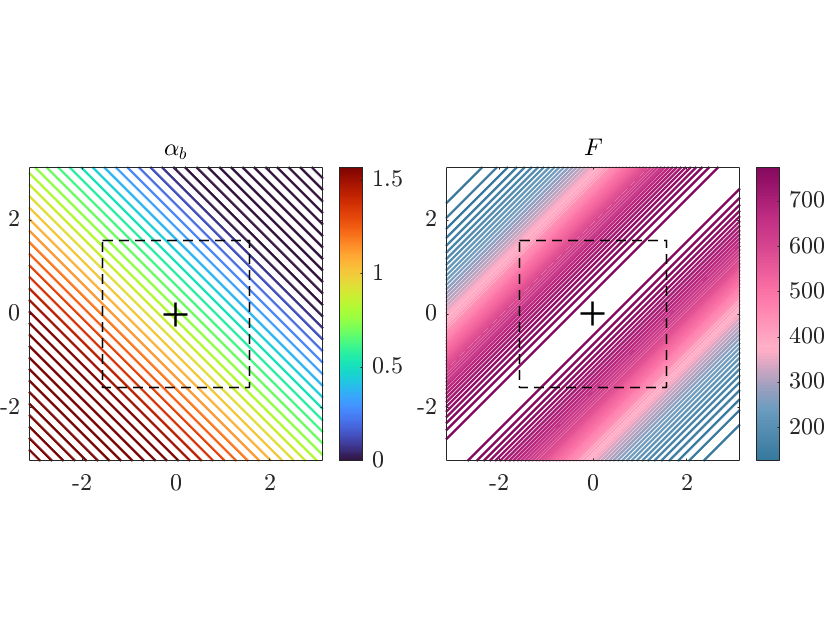

% discretized space of 2D limb angles and the sprawl angles of the surface
ai2 = clari_kin.data.sweep{cs_idx}{xdxS}(:,:,1);
aj2 = clari_kin.data.sweep{cs_idx}{ydxS}(:,:,1);
ab2_BifSurf = bifSurf_fit(ai2, aj2);
F2_BifSurf = clari_kin.functions.uF_13_f(clari_kin.params.aa, clari_kin.params.ll, ...
    ab2_BifSurf, ai2, aj2);

% % obtain a boundary for the fit and assign a polyshape
% boundIdx = boundary(aiB, ajB, 0);                                % shrink factor (last arg) zero to obtain convex hull
% inIdx = inpolygon(ai2(:), aj2(:), aiB(boundIdx), ajB(boundIdx)); % obtain the discretization indices within the delaunay triangulation
% inIdx = reshape(inIdx, size(ai2, 1), size(ai2, 2));

% create a colormap for the F-contours
colF = cell2mat(colF); colF = reshape(colF, [3, numel(colF)/3])';

% plot the bifurcation surface and fits
f = figure('Color','w'); f.WindowState = 'normal'; % maximized

t = tiledlayout('flow', 'TileSpacing', 'tight', 'Padding', 'tight');

ax1 = nexttile(t); % surface sprawl
contour(ax1, ai2, aj2, ab2_BifSurf, 50, 'LineWidth', 1.2); 
colormap(ax1, "turbo"); hold on;
plot(centr{i}(1), centr{i}(1), 'k+', 'LineWidth', 1.2, MarkerSize=12);
plot(xBox, yBox, 'k--', 'LineWidth', 0.8); 
colorbar(ax1, 'TickLabelInterpreter', 'latex', 'FontSize', fSiz); 
clim(ax1, [0 pi/2]);
axis equal; ax1.FontSize = fSiz;
title('$$\alpha_b$$', 'FontSize', fSiz);

ax2 = nexttile(t); % surface F-lvls
contour(ax2, ai2, aj2, F2_BifSurf, 50, 'LineWidth', 1.2); 
colormap(ax2, colF); hold on;
plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=12);
plot(xBox, yBox, 'k--', 'LineWidth', 0.8);
colorbar(ax2, 'TickLabelInterpreter', 'latex', 'FontSize', fSiz); 
clim(ax2, [F(1) F(end)]);
axis equal; ax2.FontSize = fSiz;
title('$$F$$', 'FontSize', fSiz);

% title(t, 'Bifurcation Surface', 'FontSize', 1.5*fSiz, 'Interpreter', 'latex');

set(gcf,'Visible','on');

Next, we find the boundaries for each F level-set and add the fit methods to the data collection section.

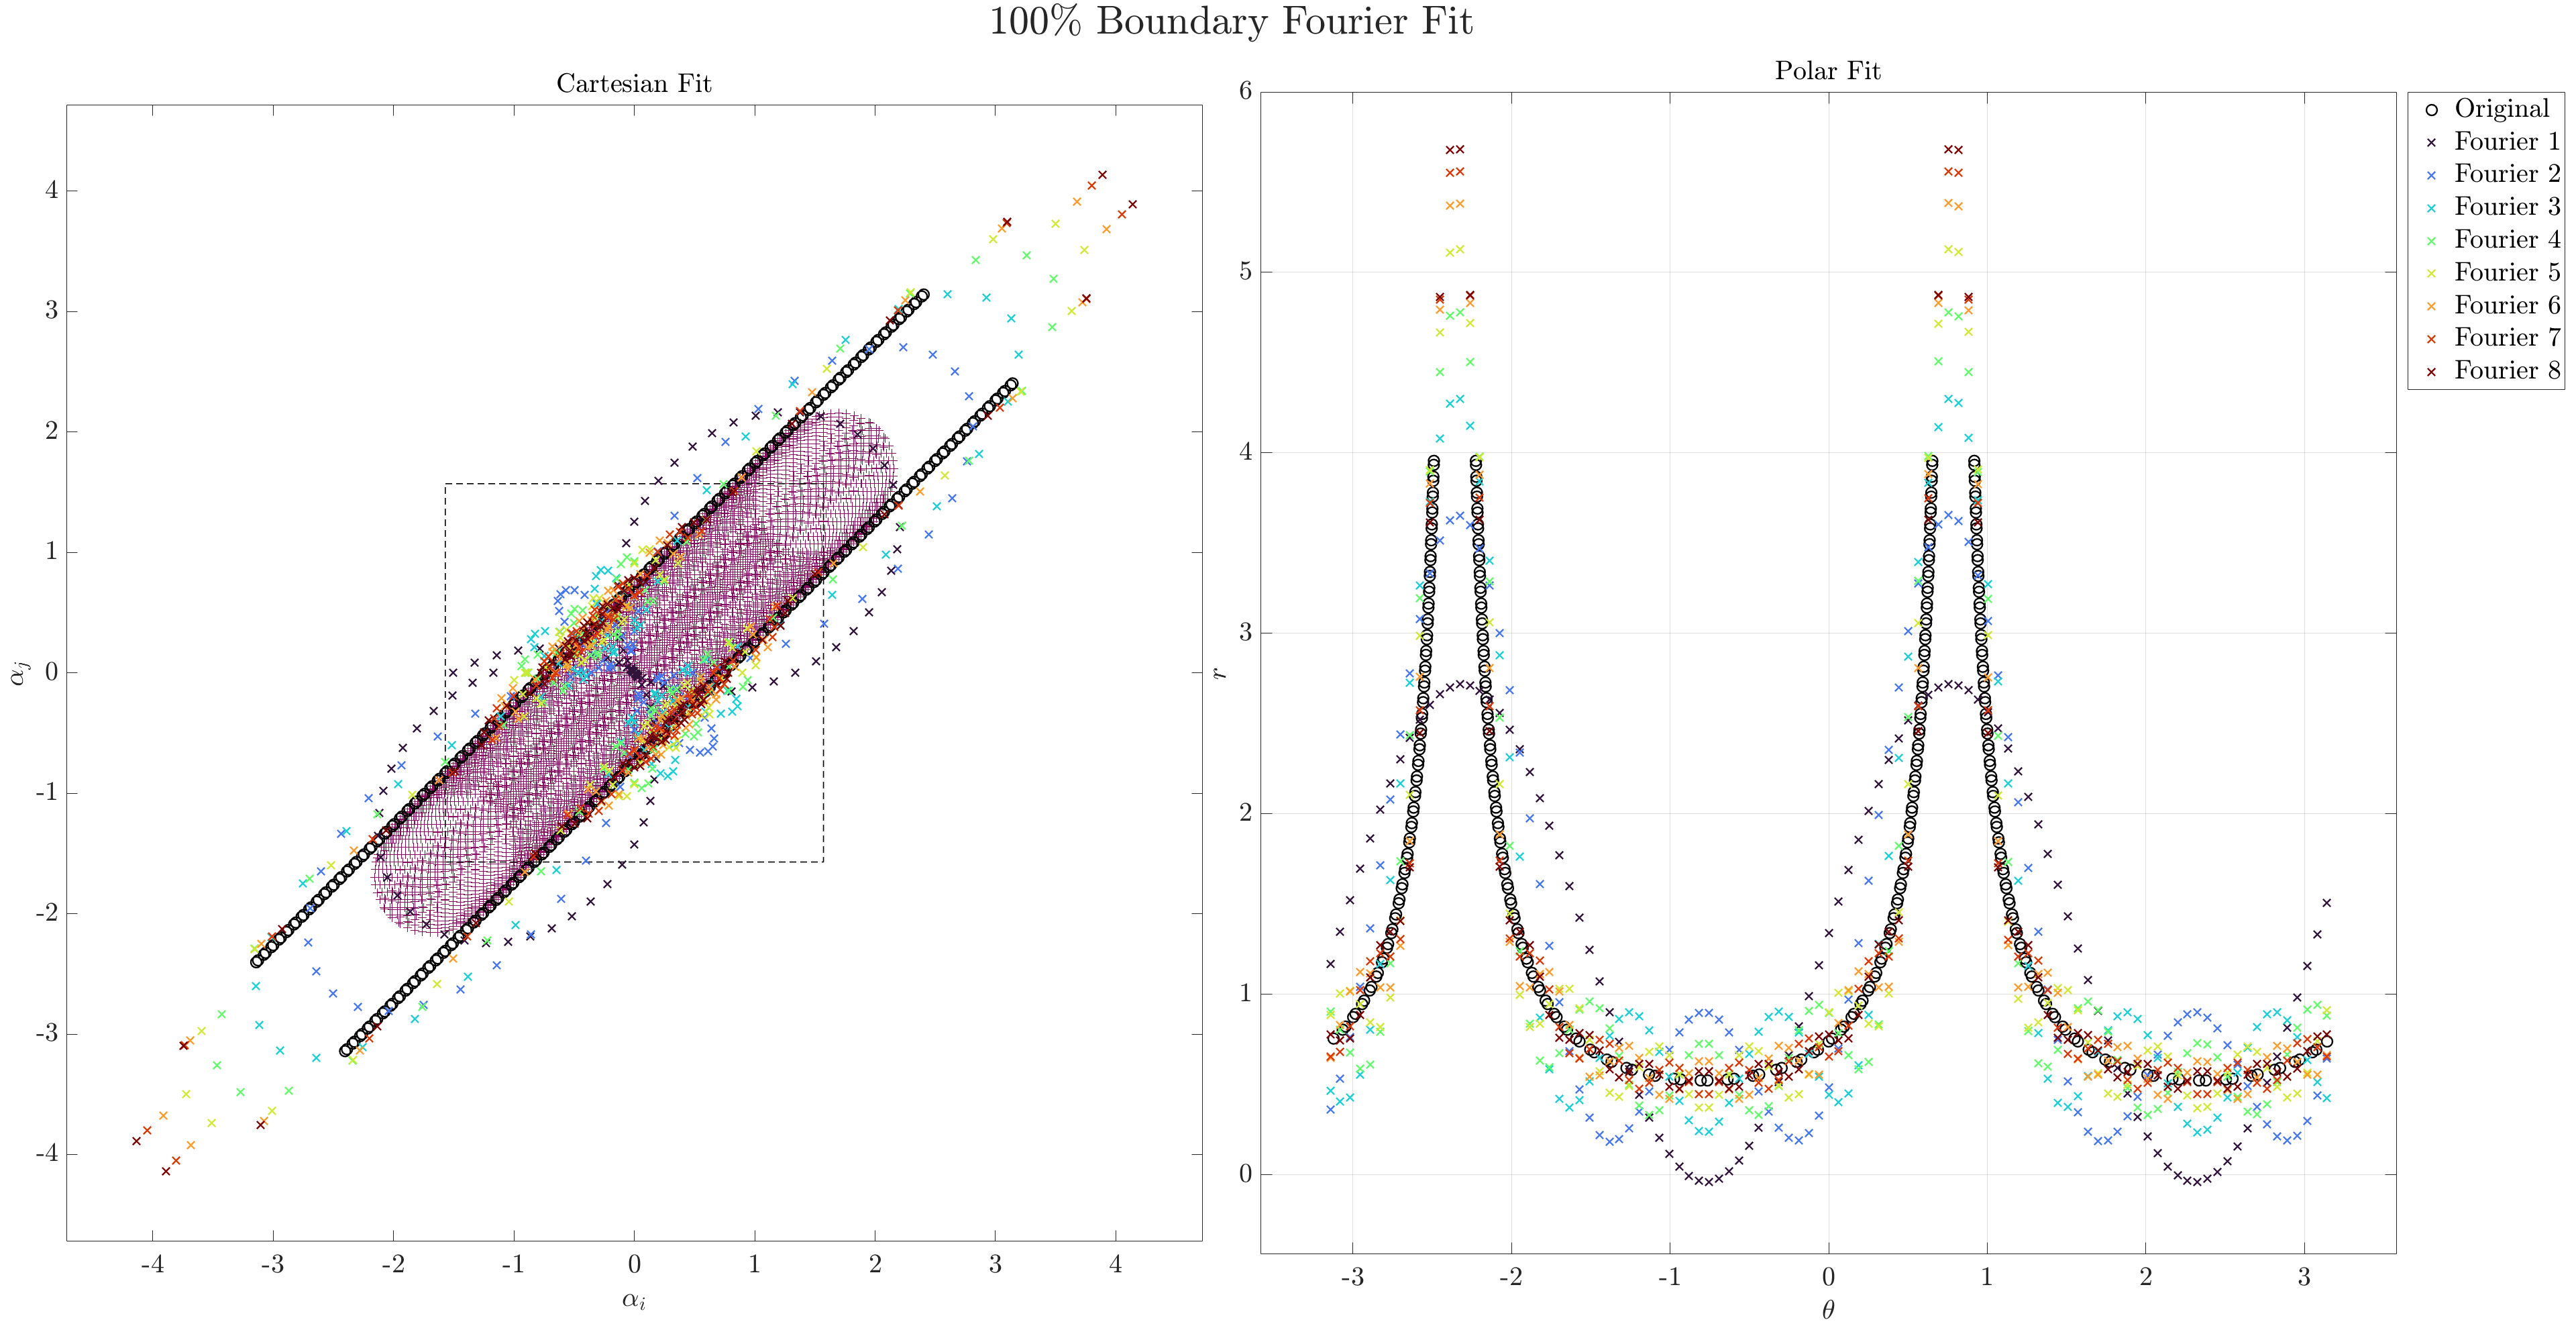

% choose the submanifold you wanna work with
cs_idx = 5;

% load the required dataset
load('Data\4clari.mat');
colF = clari_kin.plot.colF{cs_idx};
centr = clari_kin.data.centr{cs_idx};
centr3 = clari_kin.data.centr3{cs_idx};
Fctrs = clari_kin.data.Fctrs{cs_idx};
Fctrs_BifSurf = clari_kin.data.bifSurf.Fctrs{cs_idx};
FctrsP_BifSurf = clari_kin.data.bifSurf.FctrsP{cs_idx};
bifSurf_fit = clari_kin.data.bifSurf.fit{cs_idx};
ab0 = clari_kin.params.ab0;
ab_ank = clari_kin.params.ab_ank;
ank = clari_kin.params.ank;

% load params
dnum = numel(Fctrs);
xdx = 3; ydx = 4; zdx = 2;
xdxB = 2; ydxB = 3;
rdxP = 1; thdxP = 2;
swing_lim = pi*[-1, 1]; fSiz = 12;
prct = linspace(0, 100, dnum);
bCol = turbo(8);
startIdx = ceil(dnum/2); endIdx = dnum;
TH = linspace(-pi, pi, dnum);
fSiz = 20; mSiz = 8;

% get the limit box coordinates
xBox = [-clari_kin.params.ank, clari_kin.params.ank, clari_kin.params.ank, -clari_kin.params.ank];
yBox = circshift([-clari_kin.params.ank, clari_kin.params.ank, clari_kin.params.ank, -clari_kin.params.ank], -1); % swing limits
xBox(end+1) = xBox(1); yBox(end+1) = yBox(1);

% let's do the fit and check it out at a candidate value ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
i = dnum;                                                                                   % select the starting index of the F-lvl-- ceil(dnum/2), ceil(3*dnum/4), dnum
ord = 1:8;                                                                                  % test all fourier fits
rNow_fit = cell(1, 8); xNow_fit = cell(1, 8); yNow_fit = cell(1, 8);                        % initialize

xNow = Fctrs_BifSurf{i}(xdxB, :);  yNow = Fctrs_BifSurf{i}(ydxB, :);                        % cartesian boundary from F-lvl set
rNow = FctrsP_BifSurf{i}(rdxP, :); thetaNow = FctrsP_BifSurf{i}(thdxP, :);                  % polar boundary (same level set as above)
[thetaNow, sortIdx] = sort(thetaNow); rNow = rNow(sortIdx);                                 % setup for 1D-interpolation using splines
R = interp1(thetaNow, rNow, TH, "spline")';                                                 % polar boundary for theta-linspace (ordered and interpolated)

% iteratively obtain the different levels of fit
for j = 1:8
    boundNow_fit_type = ['fourier' num2str(ord(j))];                                        % fit-type (based on required order input)
    boundNow_fit = fit(TH(:), R(:), boundNow_fit_type);                                     % fourier fit for the radius of a closed boundary wrt $\theta$
    rNow_fit{j} = boundNow_fit(TH);
    xNow_fit{j} = rNow_fit{j}(:).*cos(TH(:)); yNow_fit{j} = rNow_fit{j}(:).*sin(TH(:));     % fitted result
end

% default latex interpreter
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% let's check the validity of this fit
f = figure('Color','w'); f.WindowState = 'maximized'; % maximized % normal

t = tiledlayout('flow', 'TileSpacing', 'tight', 'Padding', 'tight');

% plot in the cartesian reduced shape space
ax = nexttile(t);
plot(ax, Fctrs{i}(xdx,:), Fctrs{i}(ydx,:), '+', 'Color', colF{i});
hold(ax, "on"); axis equal square padded; ax.FontSize = fSiz;
plot(ax, centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=12);
plot(ax, xBox, yBox, 'k--', 'LineWidth', 0.8);
plot(ax, xNow, yNow, 'o', 'LineWidth', 1.2, 'Color', 'k', 'MarkerSize', mSiz);                                  % plot the original boundary (spline interpolated) 
for j = 1:8
    plot(ax, xNow_fit{j}, yNow_fit{j}, 'x', 'LineWidth', 1.2, 'Color', bCol(j, :), 'MarkerSize', mSiz);         % plot the fitted boundary for comparison 
end
xlabel(ax, '$$\alpha_i$$', 'FontSize', fSiz); ylabel(ax, '$$\alpha_j$$', 'FontSize', fSiz); 
title(ax, 'Cartesian Fit', 'Interpreter', 'latex', 'FontSize', fSiz);

% plot in the polar space
ax2 = nexttile(t);
plot(ax2, thetaNow, rNow, 'ko', 'LineWidth', 1.2, 'DisplayName', 'Original', 'MarkerSize', mSiz);               % plot the original boundary (spline interpolated)
hold(ax2, "on"); grid(ax2, "on"); axis padded; ax2.FontSize = fSiz;
for j = 1:8
    plot(ax2, TH, rNow_fit{j}, 'x', 'LineWidth', 1.2, 'Color', bCol(j, :), ...
        'DisplayName', ['Fourier ' num2str(j)], 'MarkerSize', mSiz);                                            % plot the fitted boundary for comparison 
end
ylabel(ax2, '$$r$$', 'FontSize', fSiz); xlabel(ax2, '$$\theta$$', 'FontSize', fSiz);
title(ax2, 'Polar Fit', 'Interpreter', 'latex', 'FontSize', fSiz);
legend('Location', 'NorthEastOutside', 'Interpreter', 'latex', 'FontSize', fSiz);

title(t, [num2str(prct(i)) '\% Boundary Fourier Fit'], ...
    'FontSize', 1.5*fSiz, 'Interpreter', 'latex');

set(gcf,'Visible','on');

Split the solution set above and below the boundary and visualize the surface

jNow = 8;                                                       % select just the fourier 8 boundary
FctrsNow = Fctrs{i};                                            % the current F-lvl solution set
abB_now = bifSurf_fit( FctrsNow(xdx, :), FctrsNow(ydx, :) );    % get the sprawl across the bifurcation plane
FctrsNowP = FctrsNow( FctrsNow(zdx, :) >  abB_now );            % the solution set above
FctrsNowM = FctrsNow( FctrsNow(zdx, :) <= abB_now );            % the solution set below

% fit the surfaces ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% plot surfaces ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

f = figure('Color','w'); f.WindowState = 'maximized';
t = tiledlayout('flow', 'TileSpacing', 'tight', 'Padding', 'tight');

% surface above - top view
ax = nexttile(t);
plot(ax, FctrsNowP(xdx,:), FctrsNowP(ydx,:), '+', 'Color', colF{i});
hold(ax, "on"); axis equal square padded; ax.FontSize = fSiz;
plot(ax, centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=12);
xlabel(ax, '$$\alpha_i$$', 'FontSize', fSiz); ylabel(ax, '$$\alpha_j$$', 'FontSize', fSiz); 
title(ax, 'Above solution', 'Interpreter', 'latex', 'FontSize', fSiz);

% surface above - 3D view
ax2 = nexttile(t);
plot3(ax, FctrsNowP(xdx,:), FctrsNowP(ydx,:), '+', 'Color', colF{i});
hold(ax, "on"); axis padded; ax.FontSize = fSiz;
plot3(ax, centr3{i}(2), centr3{i}(3), centr3{i}(1), 'k+', 'LineWidth', 1.2, MarkerSize=12);
xlabel(ax, '$$\alpha_i$$', 'FontSize', fSiz); ylabel(ax, '$$\alpha_j$$', 'FontSize', fSiz); 
title(ax, 'Above solution', 'Interpreter', 'latex', 'FontSize', fSiz);

title(t, [num2str(prct(i)) '\% Sprawl Surface Fit'], 'FontSize', 1.5*fSiz, 'Interpreter', 'latex');

set(gcf,'Visible','on');

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

coeffnames(bifSurf_fit_type)

ans = 21×1 cell array
    {'p00'}
    {'p10'}
    {'p01'}
    {'p20'}
    {'p11'}
    {'p02'}
    {'p30'}
    {'p21'}
    {'p12'}
    {'p03'}
    {'p40'}
    {'p31'}
    {'p22'}
    {'p13'}
    {'p04'}
    {'p50'}
    {'p41'}
    {'p32'}
    {'p23'}
    {'p14'}
    {'p05'}


formula(bifSurf_fit_type)

ans = 'p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p30*x^3 + p21*x^2*y + p12*x*y^2 + p03*y^3 + p40*x^4 + p31*x^3*y + p22*x^2*y^2 + p13*x*y^3 + p04*y^4 + p50*x^5 + p41*x^4*y + p32*x^3*y^2 + p23*x^2*y^3 + p14*x*y^4 + p05*y^5'

xx = coeffnames(bifSurf_fit_type);

xx1 = xx{1}

xx1 = 'p00'

xx1(1)

ans = 'p'

xx1(2)

ans = '0'

xx1(3)

ans = '0'

## Geometric Mechanics of Troting Contact Submanifolds

Obtain the geometric mechanics for quadrupedal robot with one internal, uncontrolled body DOF.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%   USER INPUTS   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Add folders to the path:
addpath 'Data'\ 'Utility Functions'\; load Data\4clari.mat;

% choose your active contact states, the kinematic fields to display, and
% robot configuration to display ------------------------------------------
cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];

% shape-space discretization ----------------------------------------------
dnum = 101;

% plot parameters ---------------------------------------------------------
skipV = 7.5;sV = 10; skipV = round((skipV/100)*2*floor(dnum/2)); sV = round((sV/100)*2*floor(dnum/2));
cLvl = 25; cfLvl = 100; fontscale = 1.25; fA = 1.00;
plot_info = [];
plot_info.dnum = dnum; plot_info.skipV = skipV; plot_info.sV = sV; plot_info.cLvl = cLvl; plot_info.cfLvl = cfLvl;
plot_info.fontscale = fontscale; plot_info.fA = fA;

% setup the plotting details
fields = {'-A','dz'}; configs = [ones(3,1),ones(3,1)];

% Just generate for the trot contact states
clari_kin.submanifolds = [];
clari_kin.submanifolds.list = cs; clari_kin.submanifolds.fields = fields; clari_kin.submanifolds.configs = configs;
for i = [1, 3]
    % call the function and compute everthing needed
    clari_kin = qlevel2noslip_clari(clari_kin, plot_info, i); % call the function and return the results in the kinematics structure
end